# Repeat Reunion Part 4A: Within Variance 1, Inter-Behavior Intervals and inter-type correlations

colorcodes_f = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_m = [0 0 .75 ; 0 0 .4 ; .35 .35 1];

## Transition matrices

First: raw transition matrices for each session. Both actions by the same degu ("self") and the other degu ("other") are identified as following a reference degu's action. 

TM is the first order transition matrix

TM2 is the second order transition matrix

TMc is the control transition probabilities (those expected by chance based on the numbers)



betypes = [-1 1 2 3 5];

[TM TM2 TMc] = rdb_transitionmats4(rdb_rr, betypes, 10);

TM_f = nanmean(TM(:,:,fem_ind),3);
TM_m = nanmean(TM(:,:,mal_ind),3);
TMc_f = nanmean(TMc(:,:,fem_ind),3);
TMc_m = nanmean(TMc(:,:,mal_ind),3);
    


Female

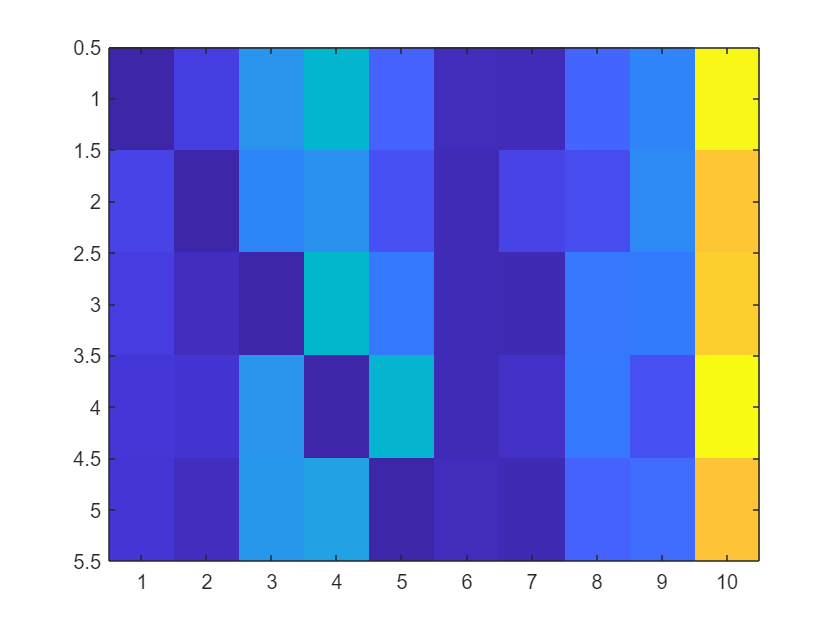

figure
igf = imagesc([TM_f(:,[1:5 7:11]) ]); %; nmcoB2(:,[1:5 7:11])]);

cm = get(get(igf, 'Parent'), 'ColorMap')

cm =     0.2422    0.1504    0.6603
    0.2444    0.1534    0.6728
    0.2464    0.1569    0.6847
    0.2484    0.1607    0.6961
    0.2503    0.1648    0.7071
    0.2522    0.1689    0.7179
    0.2540    0.1732    0.7286
    0.2558    0.1773    0.7393
    0.2576    0.1814    0.7501
    0.2594    0.1854    0.7610


Male

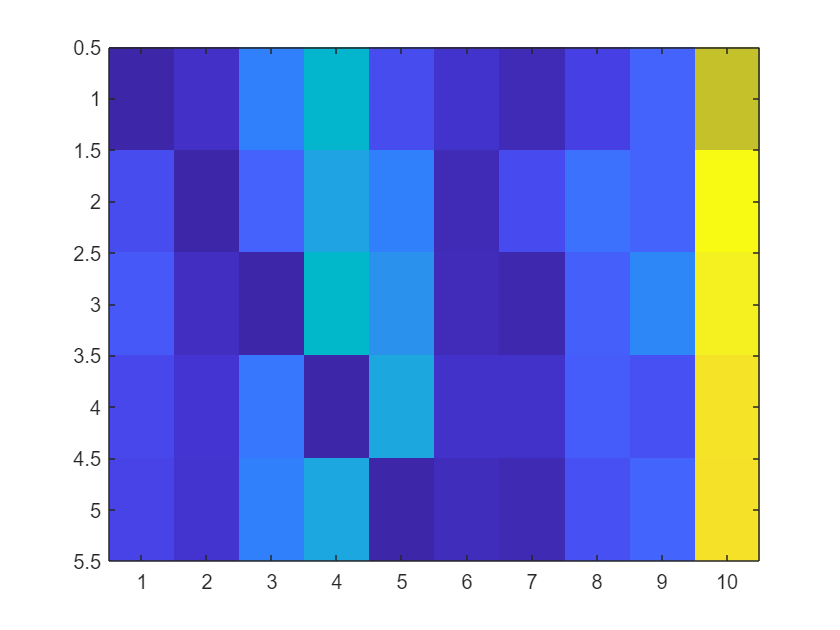

figure
igm = imagesc([TM_m(:,[1:5 7:11]) ]); %; nmcoB2(:,[1:5 7:11])]);
set(get(igm,'Parent'), 'ColorMap', cm)

### Identify the significant transitions, male and female

TMvc = TM-TMc;

for k = 1:2
    if k == 1
        curind = fem_ind;
    elseif k == 2
        curind = mal_ind;
    end

    for i = 1:5
        for j = 1:5
            [~, pTMvcS(i,j)] = ttest(TMvc(i,j,curind));
            [~, pTMvcO(i,j)] = ttest(TMvc(i,j+6,curind));    
        end
    end

    pTMvcS
    pTMvcO


    [h, cp, adj_ci_cvrg, adj_p_S] = fdr_bh([pTMvcS(1,2:5) pTMvcS(2,[1 3:5]) pTMvcS(3,[1:2 4:5]) pTMvcS(4,[1:3 5]) pTMvcS(5,[1:4])]);
    h
    adj_p_S

    [h, cp, adj_ci_cvrg, adj_p_O] = fdr_bh([pTMvcO(1,:) pTMvcO(2,:) pTMvcO(3,:) pTMvcO(4,:) pTMvcO(5,:)]);
    h
    adj_p_O



    TM2vc = TM2 - TMc;
    for i = 1:5
        for j = 1:5
            [~, pTMvcS2(i,j)] = ttest(TM2vc(i,j,curind));
            [~, pTMvcO2(i,j)] = ttest(TM2vc(i,j+6,curind));    
        end
    end

    pTMvcS2
    pTMvcO2


    [h, cp, adj_ci_cvrg, adj_p_S2] = fdr_bh([pTMvcS2(1,:) pTMvcS2(2,:) pTMvcS2(3,:) pTMvcS2(4,:) pTMvcS2(5,:)]);
    h
    adj_p_S2

    [h, cp, adj_ci_cvrg, adj_p_O2] = fdr_bh([pTMvcO2(1,:) pTMvcO2(2,:) pTMvcO2(3,:) pTMvcO2(4,:) pTMvcO2(5,:)]);
    h
    adj_p_O2
end

pTMvcS =     0.0000    0.0082    0.0000    0.0000    0.0004
    0.0086    0.0000    0.0000    0.0000    0.0151
    0.0000    0.0010    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000


pTMvcO =     0.2996    0.3433    0.0002    0.0000    0.0000
    0.4994    0.0004    0.0175    0.0003    0.0000
    0.0109    0.2735    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000
    0.0015    0.0416    0.0000    0.0000    0.0000


h = 1×20 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


adj_p_S =     0.0090    0.0000    0.0000    0.0005    0.0090    0.0000    0.0000    0.0151    0.0000    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


h = 1×25 logical array
   0   0   1   1   1   0   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1


adj_p_O =     0.3257    0.3576    0.0004    0.0001    0.0000    0.4994    0.0006    0.0218    0.0004    0.0000    0.0143    0.3108    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0021    0.0495    0.0000    0.0000    0.0000


pTMvcS2 =     0.0000    0.8395    0.0112    0.0063    0.1257
    0.2472    0.4443    0.1443    0.0248    0.3757
    0.0000    0.0254    0.0000    0.0018    0.0000
    0.0000    0.0032    0.0000    0.0000    0.0393
    0.0008    0.0035    0.0000    0.0000    0.0000


pTMvcO2 =     0.0473    0.0933    0.1503    0.5822    0.1284
    0.7238    0.7529    0.0848    0.1130    0.3628
    0.1409    0.0909    0.0006    0.0001    0.0000
    0.0064    0.0274    0.0000    0.0000    0.0006
    0.0194    0.0606    0.0000    0.0001    0.0150


h = 1×25 logical array
   1   0   1   1   0   0   0   0   1   0   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1


adj_p_S2 =     0.0000    0.8395    0.0175    0.0106    0.1571    0.2809    0.4628    0.1718    0.0352    0.4083    0.0000    0.0352    0.0000    0.0038    0.0000    0.0000    0.0062    0.0000    0.0000    0.0517    0.0018    0.0063    0.0000    0.0001    0.0000


h = 1×25 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   1   1   1   1   0   1   1   1


adj_p_O2 =     0.0909    0.1372    0.1789    0.6328    0.1690    0.7529    0.7529    0.1372    0.1569    0.4122    0.1762    0.1372    0.0020    0.0003    0.0000    0.0177    0.0571    0.0000    0.0000    0.0020    0.0440    0.1082    0.0000    0.0003    0.0375


pTMvcS =     0.0000    0.1127    0.0000    0.0000    0.0154
    0.0577    0.0000    0.0155    0.0004    0.0016
    0.0000    0.0355    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0001    0.0000    0.0000    0.0000


pTMvcO =     0.9005    0.5721    0.1027    0.0106    0.0000
    0.3487    0.0014    0.0032    0.0674    0.0000
    0.2814    0.8099    0.0000    0.0000    0.0000
    0.0136    0.0000    0.0000    0.0000    0.0000
    0.9333    0.2138    0.0000    0.0000    0.0000


h = 1×20 logical array
   0   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


adj_p_S =     0.1127    0.0000    0.0000    0.0182    0.0607    0.0182    0.0006    0.0021    0.0000    0.0395    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000


h = 1×25 logical array
   0   0   0   1   1   0   1   1   0   1   0   0   1   1   1   1   1   1   1   1   0   0   1   1   1


adj_p_O =     0.9333    0.6501    0.1427    0.0177    0.0000    0.4151    0.0026    0.0057    0.0991    0.0000    0.3517    0.8804    0.0000    0.0000    0.0000    0.0213    0.0000    0.0000    0.0000    0.0000    0.9333    0.2813    0.0000    0.0000    0.0000


pTMvcS2 =     0.0000    0.5854    0.0333    0.0267    0.3068
    0.4896    0.2562    0.0138    0.4545    0.4323
    0.0188    0.1666    0.0000    0.0004    0.0282
    0.0002    0.2470    0.0000    0.0000    0.8298
    0.3086    0.0077    0.0004    0.0000    0.0007


pTMvcO2 =     0.0009    0.0001    0.3501    0.1997    0.4321
    0.2844    0.1447    0.1166    0.0177    0.5379
    0.4549    0.1039    0.2728    0.0002    0.5865
    0.8060    0.2701    0.0001    0.0002    0.7282
    0.2267    0.7514    0.0307    0.0017    0.2397


h = 1×25 logical array
   1   0   0   0   0   0   0   1   0   0   1   0   1   1   0   1   0   1   1   0   0   1   1   1   1


adj_p_S2 =     0.0000    0.6098    0.0556    0.0504    0.3858    0.5322    0.3558    0.0313    0.5164    0.5146    0.0391    0.2604    0.0000    0.0013    0.0504    0.0010    0.3558    0.0000    0.0000    0.8298    0.3858    0.0192    0.0013    0.0000    0.0019


h = 1×25 logical array
   1   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   1   0   0   0   0   1   0


adj_p_O2 =     0.0046    0.0014    0.4862    0.4161    0.5686    0.4182    0.3289    0.2915    0.0631    0.6404    0.5686    0.2886    0.4182    0.0014    0.6665    0.8060    0.4182    0.0014    0.0014    0.7827    0.4182    0.7827    0.0959    0.0072    0.4182


Normalize by the baseline probabilties

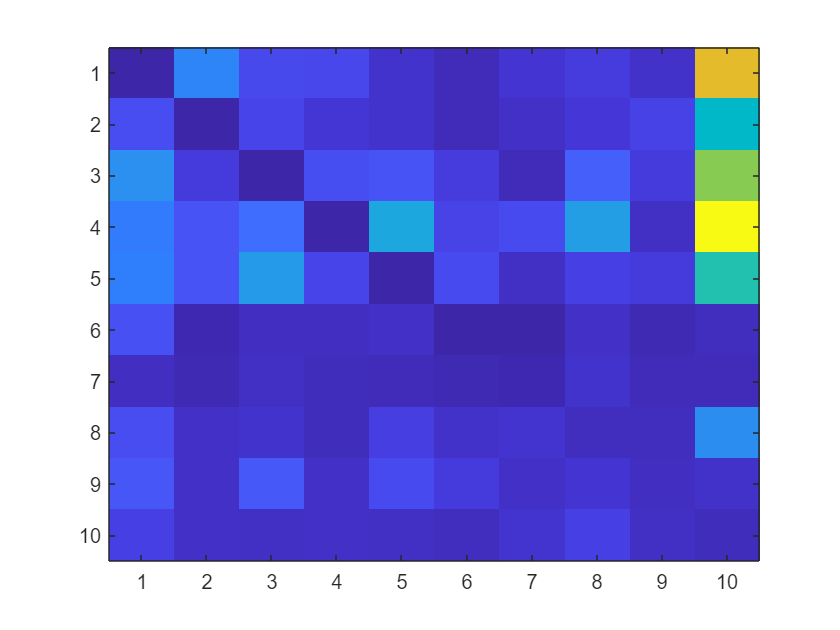


figure
TMn = TM./TMc;
TMn(isinf(TMn)) = nan;
TMnn = nanmean(TMn(:,:,fem_ind),3);
TM2n = TM2./TMc;
TM2n(isinf(TM2n)) = nan;
TM2nn = nanmean(TM2n(:,:,fem_ind),3);
%nmcoB(find(eye(length(nmcoB)))) = nan;
imagesc([TMnn(:,[1:5 7:11]) ; TM2nn(:,[1:5 7:11])]);

### Stranger vs. cagemate transitions

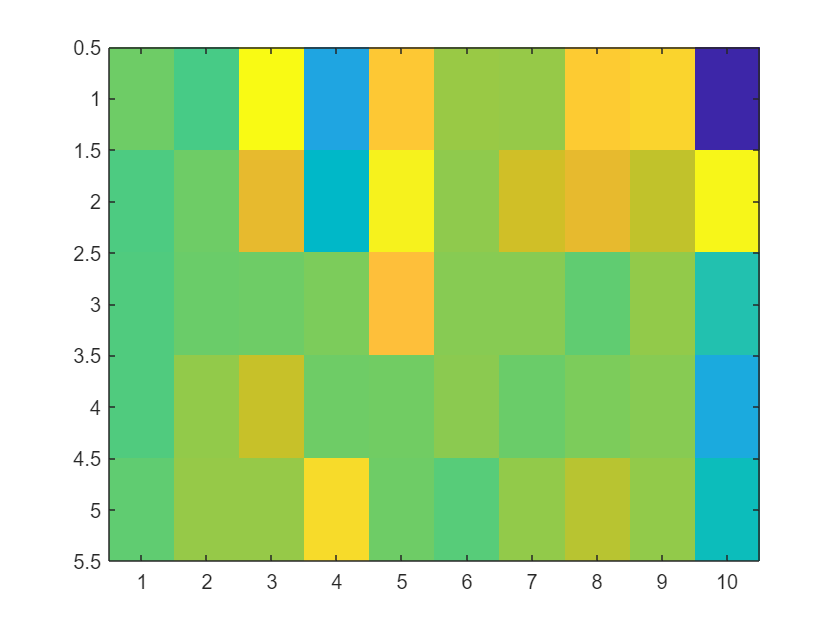

pTMcsS =        NaN    0.7011    0.0735    0.2609    0.1868
    0.7420       NaN    0.4909    0.3757    0.0125
    0.5097    0.8755       NaN    0.9174    0.0365
    0.2674    0.2443    0.1603       NaN    0.9951
    0.6407    0.0819    0.6242    0.0021       NaN


pTMcsO =     0.3734    0.5660    0.1032    0.1792    0.0356
    0.5406    0.2325    0.2528    0.6513    0.3180
    0.3103    0.4823    0.8113    0.6668    0.3941
    0.0557    0.8997    0.8409    0.5627    0.0376
    0.3065    0.0073    0.2621    0.6223    0.2279


h = 1×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1


adj_p_S =     0.8730    0.3275    0.5348    0.5336    0.8730    0.7841    0.6831    0.1245    0.7841    0.9657    0.9657    0.2434    0.5348    0.5348    0.5336    0.9951    0.8543    0.3275    0.8543    0.0428


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O =     0.6568    0.7447    0.5158    0.6116    0.3130    0.7447    0.6116    0.6116    0.7577    0.6116    0.6116    0.7447    0.8759    0.7577    0.6568    0.3480    0.8997    0.8759    0.7447    0.3130    0.6116    0.1836    0.6116    0.7577    0.6116


pTM2csS2 =     0.9415       NaN    0.7311    0.0213    0.4509
    0.4921    0.9568    0.9080    0.1926    0.1991
    0.5074    0.5508    0.0191    0.9551    0.6886
    0.1374    0.8360    0.0748    0.6123    0.1426
    0.8425    0.3000    0.0436    0.4650    0.2202


pTM2csO2 =     0.1871    0.7716    0.5321    0.2430    0.1752
    0.2342    0.3549    0.8430    0.9909    0.1067
    0.8309    0.4348    0.6902    0.3595    0.9292
    0.1198    0.0639    0.1212    0.0066    0.6114
    0.3675    0.7199    0.0354    0.9192    0.4084


h =    NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S2 =        NaN    0.9748    0.4266    0.8456    0.8456    1.0054    0.5689    0.5689    0.8456    0.8474    1.0054    0.9748    0.5689    0.9911    0.4990    0.5689    0.9911    0.7500    0.4358    0.8456


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O2 =     0.9781    0.8869    0.6076    0.5839    0.6076    0.9781    0.9909    0.4846    0.9781    0.7906    0.7350    0.9781    0.4846    0.4846    0.4846    0.9407    0.7350    0.9781    0.4846    0.9781


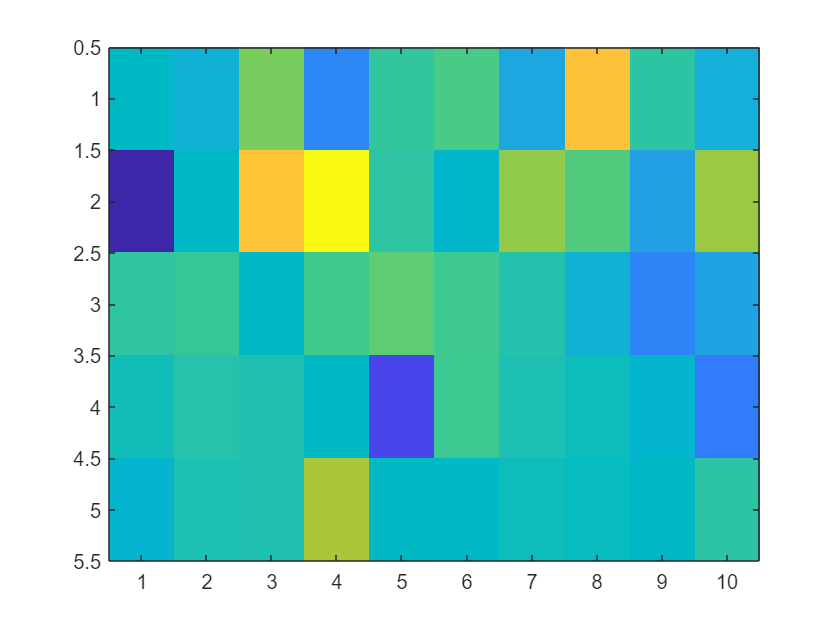

pTMcsS =        NaN    0.8146    0.5783    0.6114    0.5617
    0.1462       NaN    0.3860    0.2943    0.8531
    0.6472    0.3184       NaN    0.6544    0.5440
    0.7651    0.3710    0.7086       NaN    0.0552
    0.8178    0.6335    0.7978    0.2067       NaN


pTMcsO =     0.3097    0.5575    0.0310    0.7724    0.9077
    0.7762    0.3457    0.7283    0.7531    0.7565
    0.0075    0.2434    0.7802    0.3389    0.8004
    0.0451    0.4771    0.8124    0.8555    0.3520
    0.8940    0.7034    0.9178    0.9563    0.7851


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S =     0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531    0.8531


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O =     0.9560    0.9560    0.3761    0.9560    0.9560    0.9560    0.9560    0.9560    0.9560    0.9560    0.1879    0.9560    0.9560    0.9560    0.9560    0.3761    0.9560    0.9560    0.9560    0.9560    0.9560    0.9560    0.9560    0.9563    0.9560


pTM2csS2 =     0.6032    0.7968    0.2242    0.5694    0.7269
    0.6234    0.6681    0.6156    0.5000    0.2052
    0.8236    0.3269    0.4597    0.6881    0.5140
    0.9617    0.2419    0.0601    0.9768    0.7543
    0.6637    0.1631    0.0809    0.4631    0.0494


pTM2csO2 =     0.5176    0.3394    0.2577    0.1413    0.2239
    0.8520    0.7580    0.2161    0.8876    0.8232
    0.2096    0.2374    0.7149    0.0547    0.2156
    0.2422    0.8394    0.1699    0.0837    0.9865
    0.2763    0.1034    0.3579    0.7215    0.1332


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S2 =     0.8670    0.8063    0.8670    0.8670    0.8670    0.8670    0.8670    0.8063    0.8670    0.8670    0.8670    0.8670    0.9617    0.8063    0.8063    0.8670    0.8670    0.8063    0.8063    0.8670


h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O2 =     0.5113    0.4606    0.4606    0.4606    0.9343    0.4606    0.9343    0.9343    0.4606    0.4606    0.4606    0.4606    0.4606    0.9343    0.4606    0.9865    0.4606    0.4606    0.5113    0.9343



for k = 1:2
    if k == 1
        curind = fem_ind;
    elseif k == 2
        curind = mal_ind;
    end

    TMcagall = nanmean(TM(:,:,intersect(curind, cagemateind)),3);
    TMcagall2 = nanmean(TM2(:,:,intersect(curind, cagemateind)),3);
    TMstrall = nanmean(TM(:,:,intersect(curind, oldstrangerind)),3);
    TMstrall2 = nanmean(TM2(:,:,intersect(curind, oldstrangerind)),3);

    figure
    imagesc([TMstrall(:,[1:5 7:11]) - TMcagall(:,[1:5 7:11])]);
%imagesc([[TMcagall(:,[1:5 7:11]) ; TMcagall2(:,[1:5 7:11])]  [TMstrall(:,[1:5 7:11]) ; TMstrall2(:,[1:5 7:11])]]);
%TMvcs = TMstrall - TMcagall;

    for i = 1:5
        for j = 1:5
            [~, pTMcsS(i,j)] = ttest2(TM(i,j,intersect(curind, cagemateind)), TM(i,j,intersect(curind, oldstrangerind)));
            [~, pTMcsO(i,j)] = ttest2(TM(i,j+6,intersect(curind, cagemateind)), TM(i,j+6,intersect(curind, oldstrangerind)));        
        end
    end

    pTMcsS
    pTMcsO

    [h, cp, adj_ci_cvrg, adj_p_S] = fdr_bh([pTMcsS(1,2:5) pTMcsS(2,[1 3:5]) pTMcsS(3,[1:2 4:5]) pTMcsS(4,[1:3 5]) pTMcsS(5,[1:4])]);
    h
    adj_p_S

    [h, cp, adj_ci_cvrg, adj_p_O] = fdr_bh([pTMcsO(1,1:5) pTMcsO(2,[1:5]) pTMcsO(3,[1:5]) pTMcsO(4,[1:5]) pTMcsO(5,[1:5])]);
    h
    adj_p_O



    for i = 1:5
        for j = 1:5
            [~, pTM2csS2(i,j)] = ttest2(TM2(i,j,intersect(curind, cagemateind)), TM2(i,j,intersect(curind, oldstrangerind)));
            [~, pTM2csO2(i,j)] = ttest2(TM2(i,j+6,intersect(curind, cagemateind)), TM2(i,j+6,intersect(curind, oldstrangerind)));        
        end
    end

    pTM2csS2
    pTM2csO2


    [h, cp, adj_ci_cvrg, adj_p_S2] = fdr_bh([pTM2csS2(1,2:5) pTM2csS2(2,[1 3:5]) pTM2csS2(3,[1:2 4:5]) pTM2csS2(4,[1:3 5]) pTM2csS2(5,[1:4])]);
    h
    adj_p_S2

    [h, cp, adj_ci_cvrg, adj_p_O2] = fdr_bh([pTM2csO2(1,2:5) pTM2csO2(2,[1 3:5]) pTM2csO2(3,[1:2 4:5]) pTM2csO2(4,[1:3 5]) pTM2csO2(5,[1:4])]);
    h
    adj_p_O2

end

#### Day 1 stranger vs. cagemate transition matrices

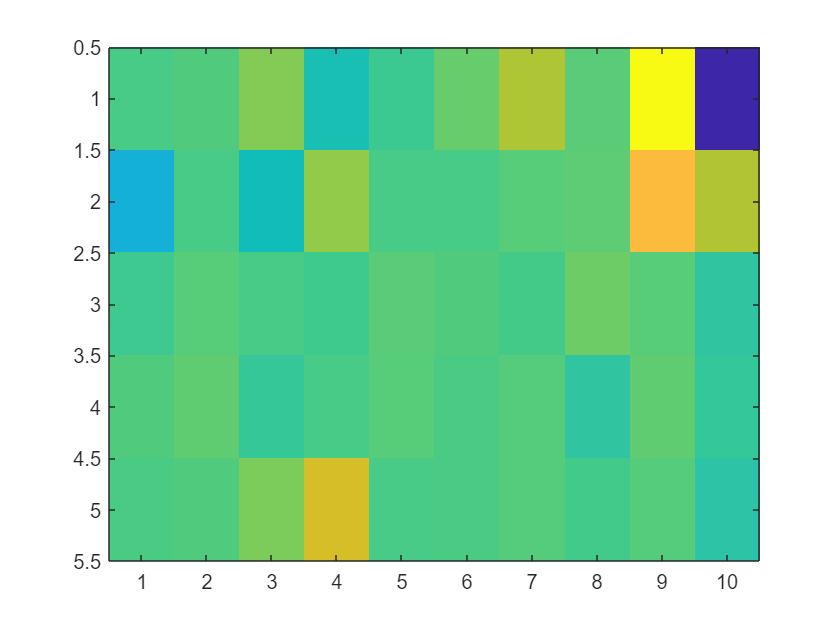

pTMcsS =        NaN    0.9570    0.6323    0.6647    0.6966
    0.3014       NaN    0.4991    0.4552       NaN
    0.5538    0.2228       NaN    0.8885    0.5199
    0.6268    0.1866    0.5426       NaN    0.7192
    0.9388    0.5968    0.3430    0.0244       NaN


pTMcsO = 5×5
    0.3451    0.3451    0.4281    0.0477    0.0178
       NaN    0.7830    0.7678    0.2253    0.6211
    0.2029    0.6332    0.4585    0.8206    0.6417
    0.5761    0.2185    0.3843    0.4191    0.6480
    0.7821    0.1959    0.9180    0.8063    0.5872


h = 1×20
     0     0     0     0     0     0     0   NaN     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S = 1×20
    1.0074    0.8990    0.8990    0.8990    0.8990    0.8990    0.8990       NaN    0.8990    0.8990    1.0074    0.8990    0.8990    0.8990    0.8990    0.8990    1.0074    0.8990    0.8990    0.4884


h = 1×25
     0     0     0     0     0   NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O = 1×25
    0.8920    0.8920    0.8920    0.5959    0.4440       NaN    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.8920    0.9562    0.8920    0.8920


pTM2csS2 = 5×5
    0.5789       NaN    0.3479    0.7387    0.8411
    0.4469    0.4469    0.0663    0.6891    0.4469
    0.9244    0.4080    0.4621    0.9823    0.9260
    0.0994    0.8673    0.2127    0.9708    0.1941
    0.3034    0.3331    0.0790    0.7232    0.8596


pTM2csO2 = 5×5
    0.3451       NaN    0.3605    0.2242    0.2448
       NaN    0.9823    0.3066    0.5444    0.4469
    0.9255    0.4906    0.7672    0.7494    0.9792
    0.9490    0.3030    0.2634    0.6100    0.4380
    0.3122    0.3331    0.0629    0.4373    0.4929


h = 1×20
   NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S2 = 1×20
       NaN    0.8126    1.0289    1.0289    0.8126    0.6628    1.0289    0.8126    1.0289    0.8126    1.0340    1.0289    0.6628    1.0289    0.8126    0.8126    0.8126    0.8126    0.6628    1.0289


h = 1×20
   NaN     0     0     0   NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O2 = 1×20
       NaN    0.7449    0.7449    0.7449       NaN    0.7449    0.7777    0.7449    1.0880    0.7547    0.9992    1.0880    1.0880    0.7449    0.7449    0.7449    0.7449    0.7449    0.7449    0.7449


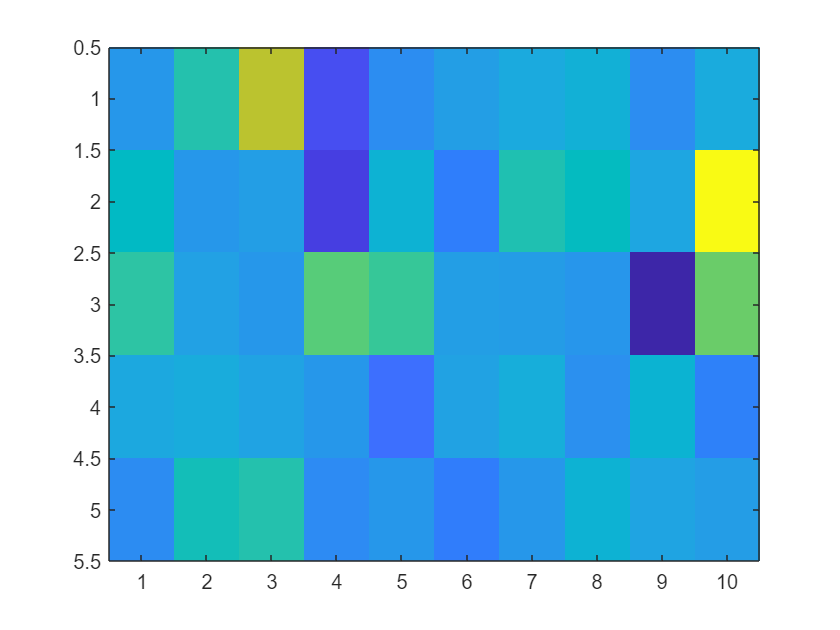

pTMcsS = 5×5
       NaN    0.1802    0.1310    0.5358    0.5953
    0.1856       NaN    0.9543    0.1939    0.7230
    0.1320    0.5631       NaN    0.3164    0.2620
    0.3179    0.2944    0.6933       NaN    0.3512
    0.7661    0.0922    0.2381    0.7354       NaN


pTMcsO = 5×5
    0.7369    0.2907    0.5383    0.9031    0.8765
    0.3162    0.1348    0.4806    0.5992    0.1594
    0.1545    0.5230    0.9770    0.0989    0.3207
    0.3103    0.1979    0.7882    0.3733    0.6900
    0.4275       NaN    0.2175    0.7851    0.9521


h = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S = 1×20
    0.5780    0.5780    0.7938    0.7938    0.5780    0.9543    0.5780    0.8064    0.5780    0.7938    0.5780    0.5780    0.5780    0.5780    0.8064    0.5854    0.8064    0.5780    0.5780    0.8064


h = 1×25
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   NaN     0     0     0


adj_p_O = 1×25
    0.9853    0.8017    0.8972    1.0177    1.0177    0.8017    0.8017    0.8972    0.9363    0.8017    0.8017    0.8972    1.0177    0.8017    0.8017    0.8017    0.8017    0.9853    0.8483    0.9853    0.8905       NaN    0.8017    0.9853    1.0177


pTM2csS2 = 5×5
    0.4093    0.3815    0.1758    0.3261    0.7030
    0.4204    0.4117    0.3928    0.7273    0.4022
    0.1934    0.6644    0.2442    0.6509    0.9534
    0.1487    0.5176    0.0561    0.0411    0.4830
    0.2977    0.5656    0.4779    0.0886    0.0224


pTM2csO2 = 5×5
    0.5043       NaN    0.3815    0.6647    0.2718
    0.2034    0.7711    0.3851    0.3812       NaN
    0.4451    0.4214    0.6134    0.1691    0.0893
    0.1052    0.5846    0.2278    0.7943    0.6032
    0.9799    0.2323    0.1370    0.3929    0.5497


h = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_S2 = 1×20
    0.7395    0.7395    0.7395    0.7655    0.7395    0.7395    0.7655    0.7395    0.7395    0.7655    0.7655    0.9534    0.7395    0.7395    0.7395    0.7395    0.7395    0.7542    0.7395    0.7395


h = 1×20
   NaN     0     0     0     0     0     0   NaN     0     0     0     0     0     0     0     0     0     0     0     0


adj_p_O2 = 1×20
       NaN    0.6358    0.7819    0.6358    0.6358    0.6358    0.6358       NaN    0.6358    0.6358    0.6358    0.6358    0.6358    0.7540    0.6358    0.7540    1.0888    0.6358    0.6358    0.6358


dayind = find(rdb_rr.exposurenum == 1);
for k = 1:2
    if k == 1
        curind = fem_ind;
    elseif k == 2
        curind = mal_ind;
    end

    curind = intersect(curind, dayind);

    TMcagall = nanmean(TM(:,:,intersect(curind, cagemateind)),3);
    TMcagall2 = nanmean(TM2(:,:,intersect(curind, cagemateind)),3);
    TMstrall = nanmean(TM(:,:,intersect(curind, oldstrangerind)),3);
    TMstrall2 = nanmean(TM2(:,:,intersect(curind, oldstrangerind)),3);

    figure
    imagesc([TMstrall(:,[1:5 7:11]) - TMcagall(:,[1:5 7:11])]);
%imagesc([[TMcagall(:,[1:5 7:11]) ; TMcagall2(:,[1:5 7:11])]  [TMstrall(:,[1:5 7:11]) ; TMstrall2(:,[1:5 7:11])]]);
%TMvcs = TMstrall - TMcagall;

    for i = 1:5
        for j = 1:5
            [~, pTMcsS(i,j)] = ttest2(TM(i,j,intersect(curind, cagemateind)), TM(i,j,intersect(curind, oldstrangerind)));
            [~, pTMcsO(i,j)] = ttest2(TM(i,j+6,intersect(curind, cagemateind)), TM(i,j+6,intersect(curind, oldstrangerind)));        
        end
    end

    pTMcsS
    pTMcsO

    [h, cp, adj_ci_cvrg, adj_p_S] = fdr_bh([pTMcsS(1,2:5) pTMcsS(2,[1 3:5]) pTMcsS(3,[1:2 4:5]) pTMcsS(4,[1:3 5]) pTMcsS(5,[1:4])]);
    h
    adj_p_S

    [h, cp, adj_ci_cvrg, adj_p_O] = fdr_bh([pTMcsO(1,1:5) pTMcsO(2,[1:5]) pTMcsO(3,[1:5]) pTMcsO(4,[1:5]) pTMcsO(5,[1:5])]);
    h
    adj_p_O



    for i = 1:5
        for j = 1:5
            [~, pTM2csS2(i,j)] = ttest2(TM2(i,j,intersect(curind, cagemateind)), TM2(i,j,intersect(curind, oldstrangerind)));
            [~, pTM2csO2(i,j)] = ttest2(TM2(i,j+6,intersect(curind, cagemateind)), TM2(i,j+6,intersect(curind, oldstrangerind)));        
        end
    end

    pTM2csS2
    pTM2csO2


    [h, cp, adj_ci_cvrg, adj_p_S2] = fdr_bh([pTM2csS2(1,2:5) pTM2csS2(2,[1 3:5]) pTM2csS2(3,[1:2 4:5]) pTM2csS2(4,[1:3 5]) pTM2csS2(5,[1:4])]);
    h
    adj_p_S2

    [h, cp, adj_ci_cvrg, adj_p_O2] = fdr_bh([pTM2csO2(1,2:5) pTM2csO2(2,[1 3:5]) pTM2csO2(3,[1:2 4:5]) pTM2csO2(4,[1:3 5]) pTM2csO2(5,[1:4])]);
    h
    adj_p_O2

end

### Compute the "sequence randomness" score, compare cagemate and stranger for both sexes

e1 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3798 0.3887 0.2709 0.3801 0.3384]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0454 0.0629 0.0562 0.0557 0.0495]
    YPositiveDelta: [0.0454 0.0629 0.0562 0.0557 0.0495]

  Show all properties


e2 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.4856 0.4158 0.3519 0.3943 0.3113]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0625 0.0580 0.0569 0.0621 0.0577]
    YPositiveDelta: [0.0625 0.0580 0.0569 0.0621 0.0577]

  Show all properties


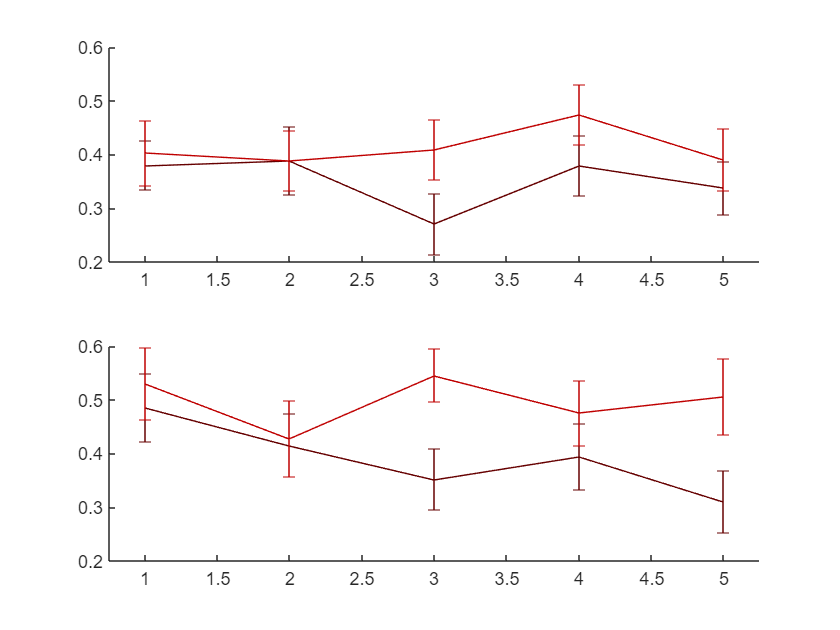

tbl = 6×8 table
                              SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                             ________    ___    ________    _______    __________    __________    __________    __________

    (Intercept)                30.108      1      30.108     244.41    1.5439e-16    1.5439e-16    1.5439e-16    1.5439e-16
    cagVstr                  0.040041      1    0.040041    0.32504       0.57258       0.57258       0.57258       0.57258
    Error                      3.9421     32     0.12319                                                                   
    (Intercept):exposures

tbl = 6×8 table
                              SumSq     DF      MeanSq        F        pValue      pValueGG     pValueHF     pValueLB 
                             _______    ___    ________    _______    _________    _________    _________    _________

    (Intercept)                49.05      1       49.05     307.47    6.179e-21    6.179e-21    6.179e-21    6.179e-21
    cagVstr                  0.27802      1     0.27802     1.7427      0.19395      0.19395      0.19395      0.19395
    Error                     6.7003     42     0.15953                                                               
    (Intercept):exposures    0.22016      4     

e1 =   ErrorBar with properties:

             Color: [0 0 0.4000]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3040 0.3235 0.2818 0.3716 0.4378]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0685 0.0664 0.0517 0.0700 0.0641]
    YPositiveDelta: [0.0685 0.0664 0.0517 0.0700 0.0641]

  Show all properties


e2 =   ErrorBar with properties:

             Color: [0 0 0.4000]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3562 0.3376 0.4083 0.4576 0.3484]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0619 0.0590 0.0694 0.0597 0.0640]
    YPositiveDelta: [0.0619 0.0590 0.0694 0.0597 0.0640]

  Show all properties


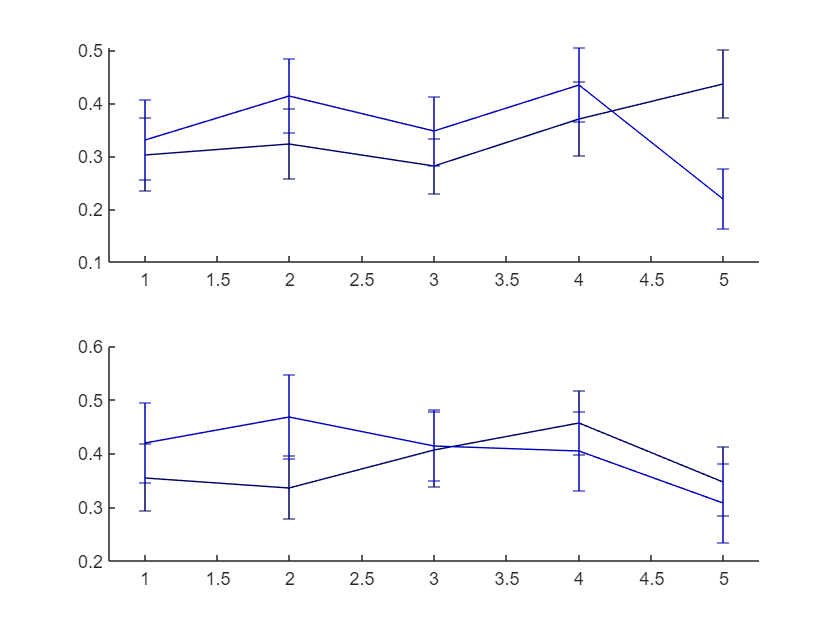

tbl = 6×8 table
                              SumSq      DF      MeanSq        F          pValue       pValueGG      pValueHF      pValueLB 
                             ________    ___    ________    ________    __________    __________    __________    __________

    (Intercept)                17.738      1      17.738      146.99    1.9611e-12    1.9611e-12    1.9611e-12    1.9611e-12
    cagVstr                  0.011573      1    0.011573    0.095899       0.75919       0.75919       0.75919       0.75919
    Error                      3.2583     27     0.12068                                                                    
    (Intercept):exposures</

tbl = 6×8 table
                              SumSq      DF      MeanSq        F          pValue       pValueGG      pValueHF      pValueLB 
                             ________    ___    ________    ________    __________    __________    __________    __________

    (Intercept)                30.266      1      30.266      205.36    1.1173e-16    1.1173e-16    1.1173e-16    1.1173e-16
    cagVstr                  0.014511      1    0.014511    0.098462       0.75545       0.75545       0.75545       0.75545
    Error                       5.453     37     0.14738                                                                    
    (Intercept):exposures</

%sr = TM_seqrand(TM);

for n = 1:2
    if n == 1
        cur_pairs = fem_pairs;
        cagemates = cagemates_f;
        ostrangers = ostrangers_f;
        colorcodes = colorcodes_f;
    elseif n == 2
        cur_pairs = mal_pairs;
        cagemates = cagemates_m;
        ostrangers = ostrangers_m;
        colorcodes = colorcodes_m;
    end

    
    
    sr_dyad_day = nan(length(cur_pairs), 5, 2);
    sr_dyad_day_ctl = nan(length(cur_pairs),5,2);

    for i = 1:length(cur_pairs)
        for j = 1:5
            curind = find(rdb_rr.paircode == cur_pairs(i) & rdb_rr.exposurenum' == j);
             TM_ = nanmean(TM(:,:,curind),3);
             TM_c = nanmean(TMc(:,:,curind),3);
    
               sr_dyad_day(i,j,1:2) = TM_seqrand(TM_);    
               sr_dyad_day_ctl(i,j,1:2) = TM_seqrand(TM_c);
    
        end
    end



    figure
    subplot(2,1,1); %The first plot here will be the "self" sequence randomness--we separately generate one for the "other" matrix
    e1 = errorbar(nanmean(sr_dyad_day(cagemates,:,1)), nanstd(sr_dyad_day(cagemates,:,1))/sqrt(length(cagemates)-1), 'Color', colorcodes(2,:))
    hold on
    errorbar(nanmean(sr_dyad_day(ostrangers,:,1)), nanstd(sr_dyad_day(ostrangers,:,1))/sqrt(length(ostrangers)-1), 'Color', colorcodes(1,:))
    box off
    set(get(e1, 'Parent'), 'XLim', [.75 5.25]);

    % Here we generate the "other" sequence randomness plot
    subplot(2,1,2)
    e2 = errorbar(nanmean(sr_dyad_day(cagemates,:,2)), nanstd(sr_dyad_day(cagemates,:,2))/sqrt(length(cagemates)-1), 'Color', colorcodes(2,:))
    hold on
    errorbar(nanmean(sr_dyad_day(ostrangers,:,2)), nanstd(sr_dyad_day(ostrangers,:,2))/sqrt(length(ostrangers)-1), 'Color', colorcodes(1,:))
    box off
    set(get(e2, 'Parent'), 'XLim', [.75 5.25]);


    tbl = simple_mixed_anova([sr_dyad_day(cagemates,:,1) ; sr_dyad_day(ostrangers,:,1)], [zeros(length(cagemates),1) ; ones(length(ostrangers), 1)], {'exposures'}, {'cagVstr'}) % between_factors, {'exposures', 'cagVstr'})

    tbl = simple_mixed_anova([sr_dyad_day(cagemates,:,2) ; sr_dyad_day(ostrangers,:,2)], [zeros(length(cagemates),1) ; ones(length(ostrangers), 1)], {'exposures'}, {'cagVstr'}) % between_factors, {'exposures', 'cagVstr'})
end

#### Now repeat for SC-HIGH and SC-LOW

e1 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3909 0.4209 0.2629 0.3777 0.3004]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0594 0.1008 0.0652 0.0773 0.0802]
    YPositiveDelta: [0.0594 0.1008 0.0652 0.0773 0.0802]

  Show all properties


e1 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3932 0.3527 0.3192 0.3626 0.2332]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0941 0.0879 0.0785 0.1019 0.0735]
    YPositiveDelta: [0.0941 0.0879 0.0785 0.1019 0.0735]

  Show all properties


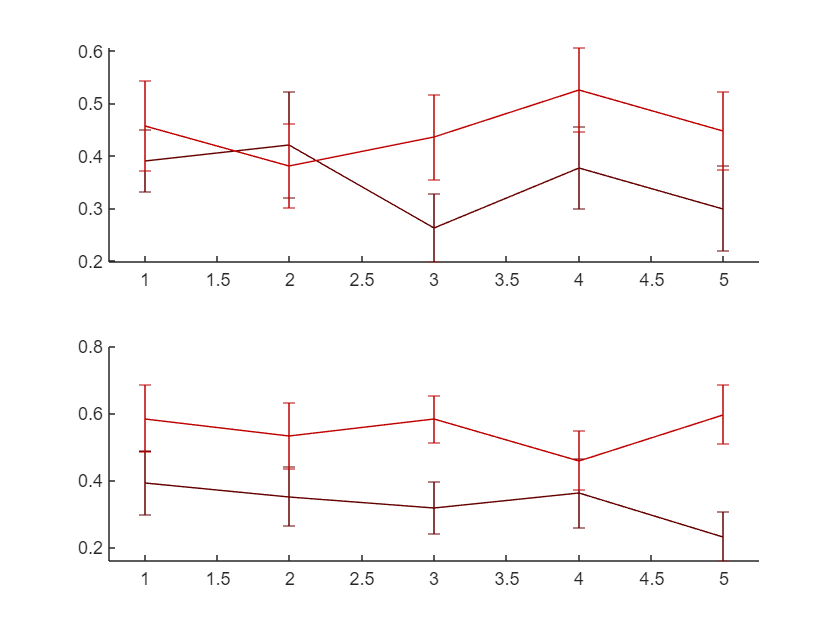

tbl = 6×8 table
                              SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                             ________    __    ________    _______    __________    __________    __________    __________

    (Intercept)                15.323     1      15.323      90.71    3.1483e-08    3.1483e-08    3.1483e-08    3.1483e-08
    cagVstr                  0.063382     1    0.063382     0.3752       0.54829       0.54829       0.54829       0.54829
    Error                      2.8718    17     0.16893                                                                   
    (Intercept):exposures   

tbl = 6×8 table
                              SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                             _______    __    ________    _______    __________    __________    __________    __________

    (Intercept)               23.872     1      23.872     143.37    7.5841e-11    7.5841e-11    7.5841e-11    7.5841e-11
    cagVstr                  0.56535     1     0.56535     3.3953      0.079545      0.079545      0.079545      0.079545
    Error                     3.4967    21     0.16651                                                                   
    (Intercept):exposures    0.14

e1 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.3726 0.3615 0.2770 0.3820 0.3732]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0697 0.0854 0.0918 0.0846 0.0652]
    YPositiveDelta: [0.0697 0.0854 0.0918 0.0846 0.0652]

  Show all properties


e1 =   ErrorBar with properties:

             Color: [0.4000 0 0]
         LineStyle: '-'
         LineWidth: 0.5000
            Marker: 'none'
             XData: [1 2 3 4 5]
             YData: [0.5582 0.4740 0.3795 0.4192 0.3727]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.0843 0.0797 0.0862 0.0825 0.0872]
    YPositiveDelta: [0.0843 0.0797 0.0862 0.0825 0.0872]

  Show all properties


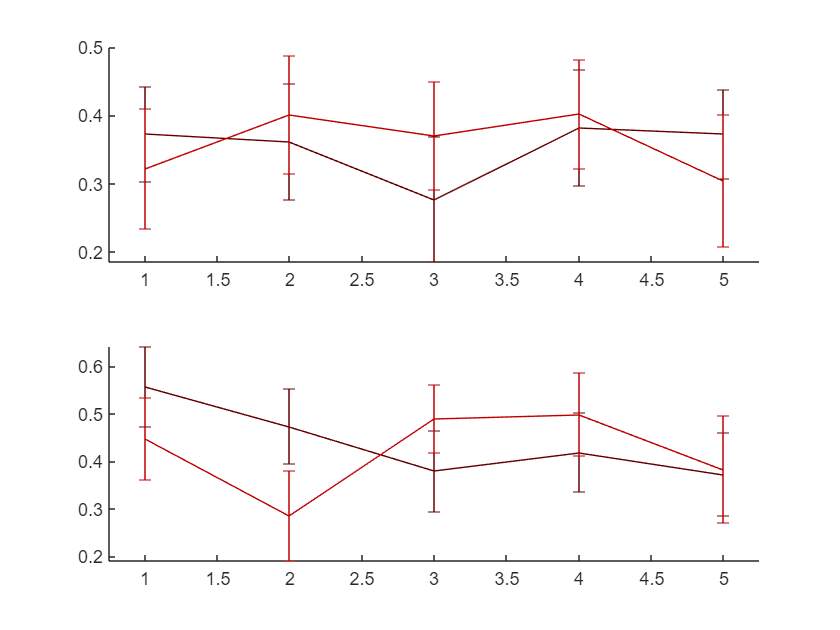

tbl = 6×8 table
                               SumSq       DF      MeanSq          F          pValue       pValueGG      pValueHF      pValueLB 
                             __________    __    __________    _________    __________    __________    __________    __________

    (Intercept)                  12.859     1        12.859       164.59    9.3389e-09    9.3389e-09    9.3389e-09    9.3389e-09
    cagVstr                  0.00057232     1    0.00057232    0.0073253        0.9331        0.9331        0.9331        0.9331
    Error                        1.0157    13      0.078129                                                                     
    (In

tbl = 6×8 table
                              SumSq      DF     MeanSq        F          pValue       pValueGG      pValueHF      pValueLB 
                             ________    __    ________    ________    __________    __________    __________    __________

    (Intercept)                20.861     1      20.861      142.89    2.7656e-10    2.7656e-10    2.7656e-10    2.7656e-10
    cagVstr                  0.011574     1    0.011574    0.079281       0.78132       0.78132       0.78132       0.78132
    Error                      2.7738    19     0.14599                                                                    
    (Intercept):exposures


        cur_pairs = fem_pairs;
        cagemates = cagemates_f;
        ostrangers = ostrangers_f;
        colorcodes = colorcodes_f;


    sr_dyad_day = nan(length(cur_pairs), 5, 2);
    sr_dyad_day_ctl = nan(length(cur_pairs),5,2);

    for i = 1:length(cur_pairs)
        for j = 1:5
            curind = find(rdb_rr.paircode == cur_pairs(i) & rdb_rr.exposurenum' == j);
             TM_ = nanmean(TM(:,:,curind),3);
             TM_c = nanmean(TMc(:,:,curind),3);
    
               sr_dyad_day(i,j,1:2) = TM_seqrand(TM_);    
               sr_dyad_day_ctl(i,j,1:2) = TM_seqrand(TM_c);
    
        end
    end




for i = 1:2
    if i == 1
        cagsig = intersect(cagemates_f, indsig_f);
        ostsig = intersect(ostrangers_f, indsig_f);
    else
        cagsig = intersect(cagemates_f, indnonsig_f);
        ostsig = intersect(ostrangers_f, indnonsig_f);
    end


figure
subplot(2,1,1)

e1 = errorbar(nanmean(sr_dyad_day(cagsig,:,1)), nanstd(sr_dyad_day(cagsig,:,1))/sqrt(length(cagsig)-1), 'Color', colorcodes_f(2,:))
hold on
errorbar(nanmean(sr_dyad_day(ostsig,:,1)), nanstd(sr_dyad_day(ostsig,:,1))/sqrt(length(ostsig)-1), 'Color', colorcodes_f(1,:))
box off
set(get(e1, 'Parent'), 'XLim', [.75 5.25]);

subplot(2,1,2)
e1 = errorbar(nanmean(sr_dyad_day(cagsig,:,2)), nanstd(sr_dyad_day(cagsig,:,2))/sqrt(length(cagsig)-1), 'Color', colorcodes_f(2,:))
hold on
errorbar(nanmean(sr_dyad_day(ostsig,:,2)), nanstd(sr_dyad_day(ostsig,:,2))/sqrt(length(ostsig)-1), 'Color', colorcodes_f(1,:))
box off
set(get(e1, 'Parent'), 'XLim', [.75 5.25]);



    tbl = simple_mixed_anova([sr_dyad_day(cagsig,:,1) ; sr_dyad_day(ostsig,:,1)], [zeros(length(cagsig),1) ; ones(length(ostsig), 1)], {'exposures'}, {'cagVstr'}) % between_factors, {'exposures', 'cagVstr'})

    tbl = simple_mixed_anova([sr_dyad_day(cagsig,:,2) ; sr_dyad_day(ostsig,:,2)], [zeros(length(cagsig),1) ; ones(length(ostsig), 1)], {'exposures'}, {'cagVstr'}) % between_factors, {'exposures', 'cagVstr'})



end

## Cross correlograms (Alternative method for behavioral sequencing)

Generate the XCorrs

betypes = [-1 1 2 3 5];

[be_xcorr_self, be_xcorr_other, xaxis, codes] = Behav_Xcorr_selfother(rdb_rr, betypes, 1, 10, 1);




[sh_xcorr_self, sh_xcorr_other, xaxis, codes] = Shuff_Xcorr_selfother(rdb_rr, betypes, 1, 10, 1);



#### Stranger vs. cagemate, separating other (first figure) and self (second figure)

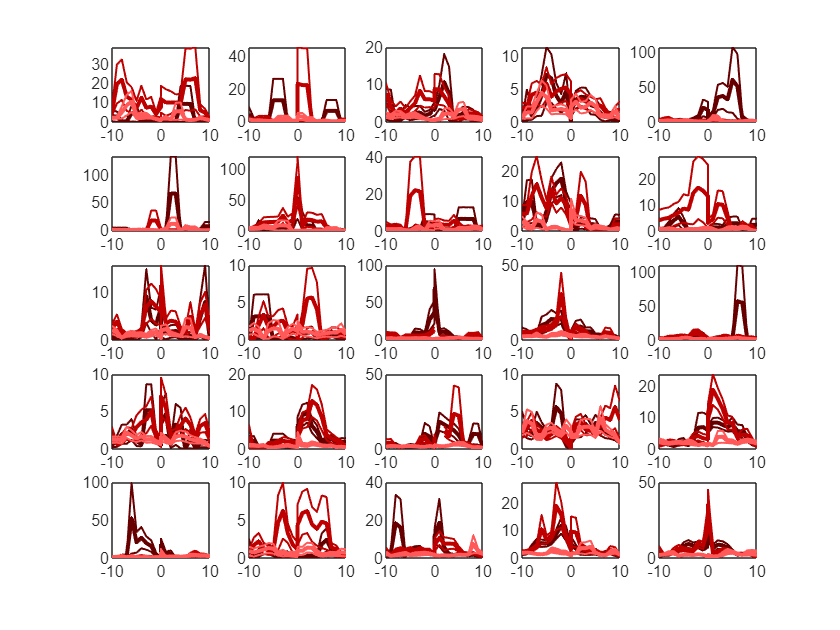

ans = 25×6
    1.0000    1.0000    0.2600    0.3658    1.1422    0.9145
    1.0000    2.0000    0.2928    0.3475   -1.0625    0.9478
    1.0000    3.0000    0.1138    0.7781    1.5940   -0.2825
    1.0000    4.0000    0.9558    0.9082   -0.0555   -0.1156
    1.0000    5.0000    0.0582    0.0098   -1.9129   -2.6265
    2.0000    1.0000    0.3433    0.3039    0.9562   -1.0381
    2.0000    2.0000    0.1757    0.5275    1.3829    0.6385
    2.0000    3.0000    0.3709    0.4365    0.8996    0.7820
    2.0000    4.0000    0.5599    0.4137   -0.5850    0.8210
    2.0000    5.0000    0.1353    0.1367    1.5073    1.5019


h = 50×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


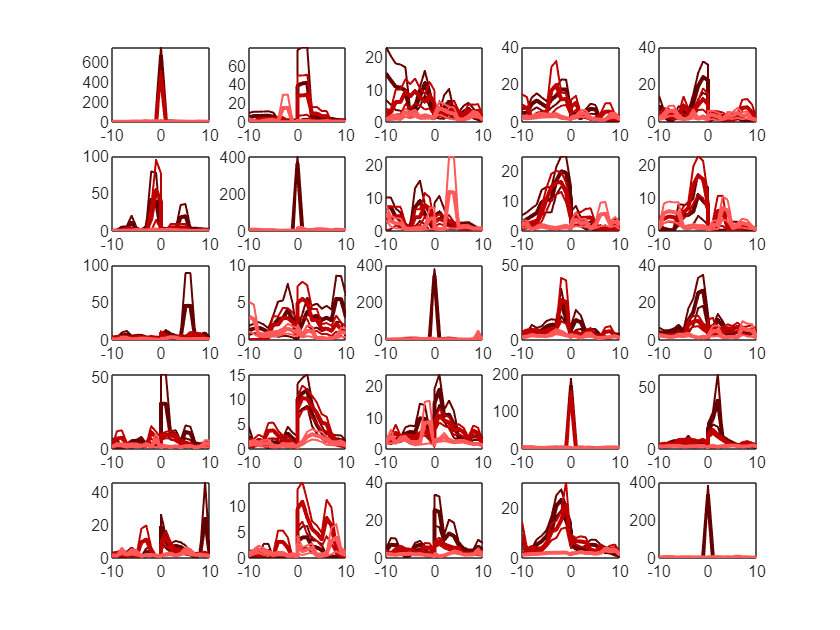

ans = 25×6
    1.0000    1.0000    0.7146    0.6765   -0.3664   -0.4182
    1.0000    2.0000    0.8503    0.8754   -0.1896   -0.1576
    1.0000    3.0000    0.6986    0.9388    0.3882   -0.0769
    1.0000    4.0000    0.9161    0.5610   -0.1055   -0.5829
    1.0000    5.0000    0.2696    0.6737   -1.1091    0.4222
    2.0000    1.0000    0.8525    0.4933   -0.1867   -0.6896
    2.0000    2.0000    0.8858    0.7195   -0.1440   -0.3602
    2.0000    3.0000    0.9307    0.9179   -0.0872   -0.1034
    2.0000    4.0000    0.7909    0.4889   -0.2659    0.6947
    2.0000    5.0000    0.3391    0.2077    0.9609    1.2688


h = 50×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


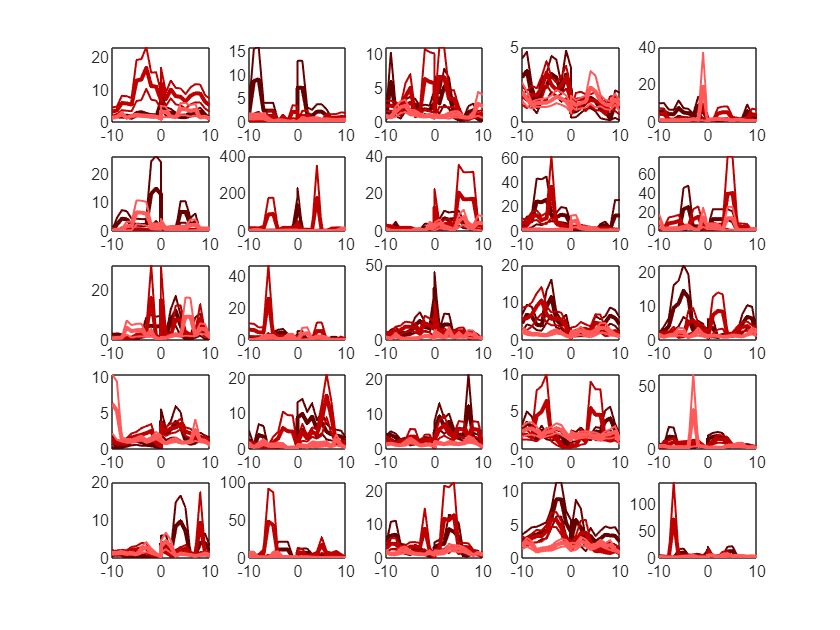

ans = 25×6
    1.0000    1.0000    0.0984    0.0688    1.6742    1.8469
    1.0000    2.0000    0.5020    0.1552    0.6759   -1.4416
    1.0000    3.0000    0.3407    0.4595    0.9568    0.7422
    1.0000    4.0000    0.9369    0.6710   -0.0793    0.4256
    1.0000    5.0000    0.2724    0.1128   -1.1033    1.5991
    2.0000    1.0000    0.1367    0.0908   -1.5107   -1.7221
    2.0000    2.0000    0.2503    0.3307    1.1724    0.9888
    2.0000    3.0000    0.5501    0.9126   -0.6013    0.1102
    2.0000    4.0000    0.7089    0.0146   -0.3748    2.5038
    2.0000    5.0000    0.7007    0.7665   -0.3866    0.2986


h = 50×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


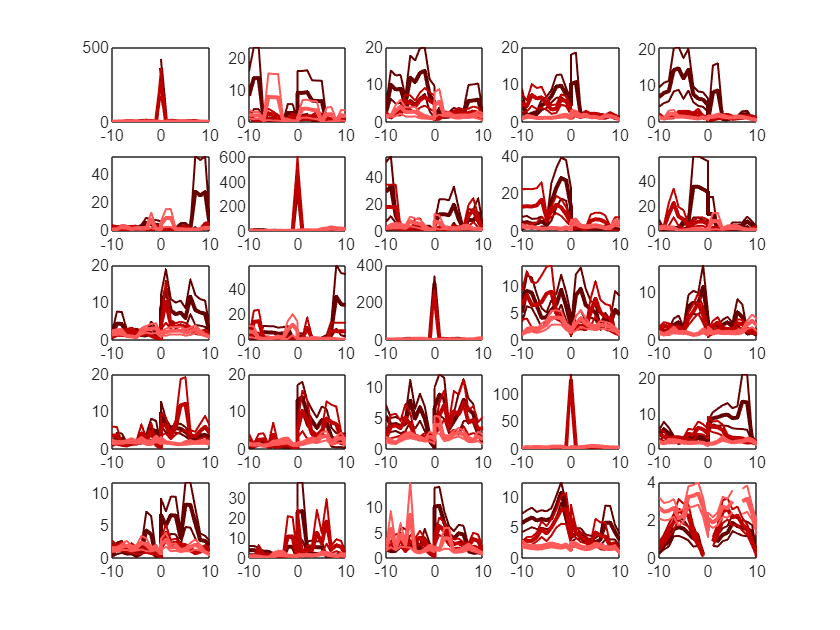

ans = 25×6
    1.0000    1.0000    0.7811    0.8297   -0.2784    0.2155
    1.0000    2.0000    0.9756    0.3057   -0.0308   -1.0337
    1.0000    3.0000    0.1839    0.6774   -1.3363   -0.4170
    1.0000    4.0000    0.1011    0.3410   -1.6501   -0.9554
    1.0000    5.0000    0.0129    0.3770   -2.5263   -0.8870
    2.0000    1.0000    0.2693    0.6915   -1.1158   -0.3989
    2.0000    2.0000    0.2405    0.1803   -1.1833   -1.3527
    2.0000    3.0000    0.6201    0.1926    0.4983   -1.3178
    2.0000    4.0000    0.2390    0.3046   -1.1875    1.0342
    2.0000    5.0000    0.1784    0.4447   -1.3649   -0.7704


h = 50×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%     colorcodesn = [.5 .5 .5];%; 0 0 0; .5 0 0 ];
% 
% 
% for i = 1:2;
% if i == 1
%     cagind = intersect(fem_ind, cagemateind);
%     strind = intersect(fem_ind, oldstrangerind);
%     allind = fem_ind;
%     colorcodes = colorcodes_f;
% else
%     cagind = intersect(mal_ind, cagemateind);
%     strind = intersect(mal_ind, oldstrangerind);
%     allind = mal_ind;
%     colorcodes = colorcodes_m;
% end
% %be_xcorr(isinf(be_xcorr)) = nan;
% figure
% %for i = 1:length(condvec)
%     for j = 1:25
%         subplot(5,5,j);
%         
% %        curind = find(rdb.condition(:,1) == condvec(i));
%         errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_other(j,:,cagind))'), nanstd(squeeze(be_xcorr_other(j,:,cagind))')/sqrt(length(find(~isnan(be_xcorr_other(j,10,cagind))))-1), 'Color', colorcodes(2,:))  ;  
%         hold on
%         errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_other(j,:,strind))'), nanstd(squeeze(be_xcorr_other(j,:,strind))')/sqrt(length(find(~isnan(be_xcorr_other(j,10,strind))))-1), 'Color', colorcodes(1,:))  ;
%         errorbar_alt(xaxis, nanmean(squeeze(sh_xcorr_other(j,:,allind))'), nanstd(squeeze(sh_xcorr_other(j,:,allind))')/sqrt(length(find(~isnan(sh_xcorr_other(j,10,allind))))-1), 'Color', colorcodesn)  ; 
%    %     box off
%   %      errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,strind))'), nanstd(squeeze(be_xcorr(j,:,strind))')/sqrt(length(strind)-1), 'Color', colorcodes(3,:))  ;  
%     end  
% end



colorcodesn = [.5 .5 .5];%; 0 0 0; .5 0 0 ];
for n = 1:2
    if n == 1
        sexind = fem_ind;
                colorcodes = colorcodes_f;
    else
        sexind = mal_ind;
            colorcodes = colorcodes_m;
    end


        %IF FOCUSING ON SPECIFIC DAYS, USE THE FOLLOWING

        dayind = find(rdb_rr.exposurenum < 6);
        %dayind = find(rdb_rr.exposurenum == 1);
        sexind = intersect(dayind, sexind);        
    %
    
   
        cagind = intersect(sexind, cagemateind);
        strind = intersect(sexind, oldstrangerind);
        allind = sexind;


    %OTHER

    figure
    %for i = 1:length(condvec)
    for j = 1:25
        subplot(5,5,j);
        
%        curind = find(rdb.condition(:,1) == condvec(i));
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_other(j,:,cagind))'), nanstd(squeeze(be_xcorr_other(j,:,cagind))')/sqrt(length(find(~isnan(be_xcorr_other(j,10,cagind))))-1), 'Color', colorcodes_f(2,:))  ;  
        hold on
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_other(j,:,strind))'), nanstd(squeeze(be_xcorr_other(j,:,strind))')/sqrt(length(find(~isnan(be_xcorr_other(j,10,strind))))-1), 'Color', colorcodes_f(1,:))  ;
        errorbar_alt(xaxis, nanmean(squeeze(sh_xcorr_other(j,:,allind))'), nanstd(squeeze(sh_xcorr_other(j,:,allind))')/sqrt(length(find(~isnan(sh_xcorr_other(j,10,allind))))-1), 'Color', colorcodes_f(3,:))  ; 
   %     box off
  %      errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,strind))'), nanstd(squeeze(be_xcorr(j,:,strind))')/sqrt(length(strind)-1), 'Color', colorcodes(3,:))  ;  
    end  

    mxcS = nan(size(be_xcorr_other,1), 2, length(strind));
    mxcC = nan(size(be_xcorr_other,1), 2, length(cagind));

    mxcS(:,1,:) = nanmean(be_xcorr_other(:,6:10,strind),2);
    mxcS(:,2,:) = nanmean(be_xcorr_other(:,13:17,strind),2);

    mxcC(:,1,:) = nanmean(be_xcorr_other(:,6:10,cagind),2);
    mxcC(:,2,:) = nanmean(be_xcorr_other(:,13:17,cagind),2);

%sxc(:,1,:) = nanmean(SH_xcorr(:,12:21,:),2);
%sxc(:,2,:) = nanmean(SH_xcorr(:,22:31,:),2);

%curind = find(ismember(rdb.condition(:,1), condvec));

% for a while the below wasn't working because "b1" (and others) had been
% assigned to serve as handles to a deleted bar in a plot. If this happens,
% clear b1, bb1, etc.

    clear aSC1 aSC2 bSC1 bSC2 dSC1 dSC2

    for i = 1:25
        [aSC1(i), bSC1(i), ~, dSC1(i)] = ttest2(squeeze(mxcS(i,1,:)), squeeze(mxcC(i,1,:)));
        [aSC2(i), bSC2(i), ~, dSC2(i)] = ttest2(squeeze(mxcS(i,2,:)), squeeze(mxcC(i,2,:)));
    end

    [codes(1:25,1:2,1) bSC1' bSC2' [dSC1(:).tstat]' [dSC2(:).tstat]']

    h = fdr_bh([bSC1' ; bSC2'])

    %SELF

figure
%for i = 1:length(condvec)
    for j = 1:25
        subplot(5,5,j);
        
%        curind = find(rdb.condition(:,1) == condvec(i));
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_self(j,:,cagind))'), nanstd(squeeze(be_xcorr_self(j,:,cagind))')/sqrt(length(find(~isnan(be_xcorr_self(j,10,cagind))))-1), 'Color', colorcodes_f(2,:))  ;  
        hold on
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr_self(j,:,strind))'), nanstd(squeeze(be_xcorr_self(j,:,strind))')/sqrt(length(find(~isnan(be_xcorr_self(j,10,strind))))-1), 'Color', colorcodes_f(1,:))  ;
        errorbar_alt(xaxis, nanmean(squeeze(sh_xcorr_self(j,:,allind))'), nanstd(squeeze(sh_xcorr_self(j,:,allind))')/sqrt(length(find(~isnan(sh_xcorr_self(j,10,allind))))-1), 'Color', colorcodes_f(3,:))  ; 
   %     box off
  %      errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,strind))'), nanstd(squeeze(be_xcorr(j,:,strind))')/sqrt(length(strind)-1), 'Color', colorcodes(3,:))  ;  
    end  

    mxcS = nan(size(be_xcorr_self,1), 2, length(strind));
    mxcC = nan(size(be_xcorr_self,1), 2, length(cagind));

    mxcS(:,1,:) = nanmean(be_xcorr_self(:,6:10,strind),2);
    mxcS(:,2,:) = nanmean(be_xcorr_self(:,13:17,strind),2);

    mxcC(:,1,:) = nanmean(be_xcorr_self(:,6:10,cagind),2);
    mxcC(:,2,:) = nanmean(be_xcorr_self(:,13:17,cagind),2);

%sxc(:,1,:) = nanmean(SH_xcorr(:,12:21,:),2);
%sxc(:,2,:) = nanmean(SH_xcorr(:,22:31,:),2);

%curind = find(ismember(rdb.condition(:,1), condvec));

% for a while the below wasn't working because "b1" (and others) had been
% assigned to serve as handles to a deleted bar in a plot. If this happens,
% clear b1, bb1, etc.

    clear aSC1 aSC2 bSC1 bSC2 dSC1 dSC2

    for i = 1:25
        [aSC1(i), bSC1(i), ~, dSC1(i)] = ttest2(squeeze(mxcS(i,1,:)), squeeze(mxcC(i,1,:)));
        [aSC2(i), bSC2(i), ~, dSC2(i)] = ttest2(squeeze(mxcS(i,2,:)), squeeze(mxcC(i,2,:)));
    end

    [codes(1:25,1:2,1) bSC1' bSC2' [dSC1(:).tstat]' [dSC2(:).tstat]']

    h = fdr_bh([bSC1' ; bSC2'])


end   

### Collapse self and other for cleaner figures & results

betypes = [-1 1 2 3 5];

[be_xcorr, xaxis, codes] = Behav_Xcorr(rdb_rr.be_start_end, rdb_rr.be_identcode, betypes, rdb_rr.sessionstart_end);
[SH_xcorr, xaxis, codes] = Shuff_Behav_Xcorr2(rdb_rr.be_start_end, rdb_rr.be_identcode, betypes, rdb_rr.sessionstart_end);
colorcodes = [.5 .5 .5];

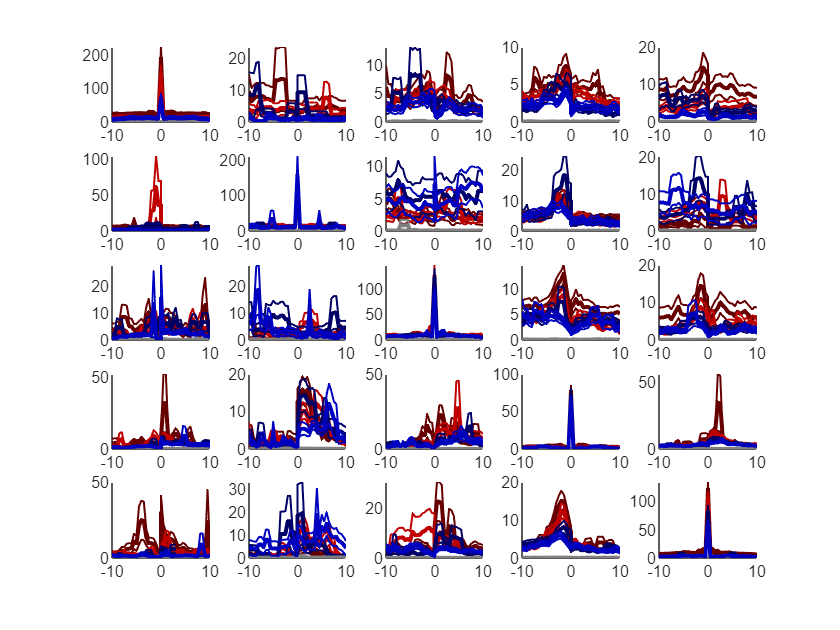

ans = 25×6
1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.4421    0.4417
    0.0001    0.0002         0         0    0.1344    0.1350
    0.0001    0.0003    0.0001         0    0.4929    0.4817
    0.0001    0.0004         0         0    0.4882    0.4900
    0.0001    0.0005         0         0    0.4359    0.4139
    0.0002    0.0001         0         0    0.1279    0.1243
    0.0002    0.0002         0         0    0.2767    0.2733
    0.0002    0.0003         0         0    0.2457    0.2538
    0.0002    0.0004         0         0    0.2642    0.2669
    0.0002    0.0005    0.0001    0.0001    0.2975    0.2916


h = 50×1 logical array
   0
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1


ans = 25×6
1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.4994    0.5008
    0.0001    0.0002         0         0    0.1142    0.1073
    0.0001    0.0003         0         0    0.4626    0.4497
    0.0001    0.0004         0         0    0.5730    0.6297
    0.0001    0.0005         0         0    0.3003    0.3350
    0.0002    0.0001         0         0    0.1042    0.1098
    0.0002    0.0002         0         0    0.1647    0.1643
    0.0002    0.0003         0         0    0.1156    0.1095
    0.0002    0.0004         0         0    0.1512    0.1671
    0.0002    0.0005         0         0    0.0870    0.0932


h = 50×1 logical array
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   0
   1
   1
   1
   1
   1
   1



figure

for n = 1:2
    if n == 1
        sexind = fem_ind;
                colorcodes = colorcodes_f;
    else
        sexind = mal_ind;
            colorcodes = colorcodes_m;
    end


        %IF FOCUSING ON SPECIFIC DAYS, USE THE FOLLOWING

        dayind = find(rdb_rr.exposurenum < 6);
       % dayind = find(rdb_rr.exposurenum == 1);
        sexind = intersect(dayind, sexind);        
    %
    
   
        cagind = intersect(sexind, cagemateind);
        strind = intersect(sexind, oldstrangerind);
        allind = sexind;

        i = 1;


%for i = 1:length(condvec)
    for j = 1:25
        subplot(5,5,j);
       hold on 
%        curind = find(rdb.condition(:,1) == condvec(i));
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,cagind))'), nanstd(squeeze(be_xcorr(j,:,cagind))')/sqrt(length(find(~isnan(nanmean(squeeze(be_xcorr(j,:,cagind))',2))))-1), 'Color', colorcodes(2,:))  ;  
        errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,cagind))'), nanstd(squeeze(SH_xcorr(j,:,cagind))')/sqrt(length(find(~isnan(nanmean(squeeze(SH_xcorr(j,:,cagind))',2))))-1), 'Color', colorcodesn)  ; 
        errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,strind))'), nanstd(squeeze(be_xcorr(j,:,strind))')/sqrt(length(find(~isnan(nanmean(squeeze(be_xcorr(j,:,strind))',2))))-1), 'Color', colorcodes(1,:))  ;
        box off
    end   


 mxcS = nan(size(be_xcorr,1), 2, length(strind));
    mxcC = nan(size(be_xcorr,1), 2, length(cagind));

    mxcS(:,1,:) = nanmean(be_xcorr(:,12:21,strind),2);
    mxcS(:,2,:) = nanmean(be_xcorr(:,22:31,strind),2);

    mxcC(:,1,:) = nanmean(be_xcorr(:,12:21,cagind),2);
    mxcC(:,2,:) = nanmean(be_xcorr(:,22:31,cagind),2);

%sxc(:,1,:) = nanmean(SH_xcorr(:,12:21,:),2);
%sxc(:,2,:) = nanmean(SH_xcorr(:,22:31,:),2);

%curind = find(ismember(rdb.condition(:,1), condvec));

% for a while the below wasn't working because "b1" (and others) had been
% assigned to serve as handles to a deleted bar in a plot. If this happens,
% clear b1, bb1, etc.

    clear aSC1 aSC2 bSC1 bSC2 dSC1 dSC2

    for i = 1:25
  %      [~, bSC1(i), ~, dSC1(i)] = ttest2(squeeze(mxcS(i,1,:)), squeeze(mxcC(i,1,:)));
  %      [~, bSC2(i), ~, dSC2(i)] = ttest2(squeeze(mxcS(i,2,:)), squeeze(mxcC(i,2,:)));
        [~, bSC1(i), dSC1(i)] = ranksum(squeeze(mxcS(i,1,:)), squeeze(mxcC(i,1,:)));
        [~, bSC2(i), dSC2(i)] = ranksum(squeeze(mxcS(i,2,:)), squeeze(mxcC(i,2,:)));
    end

 %   [codes(1:25,1:2,1) bSC1' bSC2' [dSC1(:).tstat]' [dSC2(:).tstat]']

    [codes(1:25,1:2,1) bSC1' bSC2' [dSC1(:).ranksum]' [dSC2(:).ranksum]']

    h = fdr_bh([bSC1' ; bSC2'])




    
end

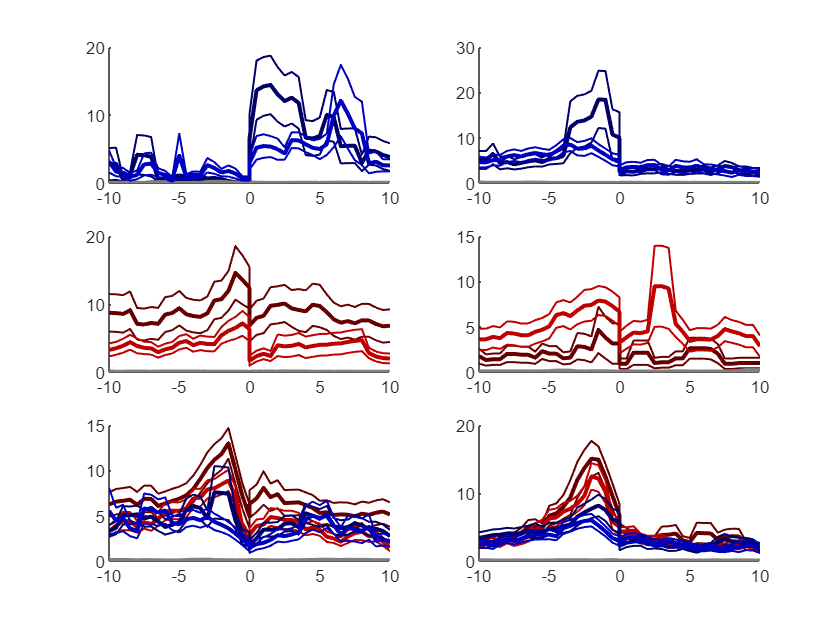


%for the paper figure

cuvec = [17 2 ; 9 2 ;...  % male FF x GR, GR x FF ::: 17 , 9
         5  1 ; 10 1 ;...  %female AG x BS,  GR x BS ::: 5 , 10
         14 1 ; 24 1 ;...
         14 2 ; 24 2 ];%male & female RS x FF, BS x FF ::: 14 , 24


figure
for i = 1:size(cuvec,1)
    j = cuvec(i,1);
    n = cuvec(i,2);
       
    if i > 6
        subplot(3,2,i-2);
    else
        subplot(3,2,i);
    end
    if n == 1
        sexind = fem_ind;
        colorcodes = colorcodes_f;
    else
        sexind = mal_ind;
        colorcodes = colorcodes_m;
    end
    dayind = find(rdb_rr.exposurenum < 6);
    sexind = intersect(dayind, sexind); 
    
    cagind = intersect(sexind, cagemateind);
    strind = intersect(sexind, oldstrangerind);
    allind = sexind;

    errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,cagind))'), nanstd(squeeze(be_xcorr(j,:,cagind))')/sqrt(length(find(~isnan(nanmean(squeeze(be_xcorr(j,:,cagind))',2))))-1), 'Color', colorcodes(2,:))  ;  
    errorbar_alt(xaxis, nanmean(squeeze(SH_xcorr(j,:,cagind))'), nanstd(squeeze(SH_xcorr(j,:,cagind))')/sqrt(length(find(~isnan(SH_xcorr(j,:,cagind))))-1), 'Color', colorcodesn)  ; 
    errorbar_alt(xaxis, nanmean(squeeze(be_xcorr(j,:,strind))'), nanstd(squeeze(be_xcorr(j,:,strind))')/sqrt(length(find(~isnan(nanmean(squeeze(be_xcorr(j,:,strind))',2))))-1), 'Color', colorcodes(1,:))  ;
    box off
end

## Compute the inter-interaction-intervals

Inter-interaction intervals for each type of interaction (most interesting may be face-face)

#### All IIIs

%all_IBI 


betypes = [-1 1 2 3 5];


    
    all_IBI = cell(length(fem_pairs), length(betypes),2);
    all_IBId = cell(length(fem_pairs), length(betypes),2); %for local variance
    all_IBIs = cell(length(fem_pairs), length(betypes),2); % for local variance

for n = 1:2

     if n == 1
        curpairs = fem_pairs;
    elseif n == 2
        curpairs = mal_pairs;
     end

    for i = 1:length(curpairs)
        curind = find(rdb_rr.paircode == curpairs(i) & rdb_rr.exposurenum' < 6);   
        for j = 1:length(curind)        
            for k = 1:length(betypes)
                for m = 1:2
                    m_who = find(rdb_rr.be_who(:,m,curind(j)));
                    p_curbehaves = find(fix(rdb_rr.be_identcode(:,curind(j))) == betypes(k));
                    curbehaves = intersect(m_who, p_curbehaves);
                    IBI = diff(rdb_rr.be_start_end(curbehaves,1,curind(j)));
                    all_IBI{i,k,n} = [all_IBI{i,k,n} ; IBI];
                    if length(IBI) > 1
                        all_IBId{i,k,n} = [all_IBId{i,k,n} ; IBI(1:end-1) - IBI(2:end)];
                        all_IBIs{i,k,n} = [all_IBIs{i,k,n} ; IBI(1:end-1) + IBI(2:end)];
                    end
                end
            end        
        end
    end
end

#### Generate figures to better assess IBI distributions

(Distributions are exponential, Local Variance serves as a practical measure of variance that does not scale with number of events)

Based on Shinomoto and kyama (biosystems 2005), who cite Cox and Lewis 1966, an estimate of the coefficient of variation and local variation.

Cv = std(intervals) /  mean(intervals) 

Lv = 1/(n-1) x sum(3(Ti-Ti+1)^2/(T+Ti+1)^2;

plot the ISI for a particularly high frequency session:

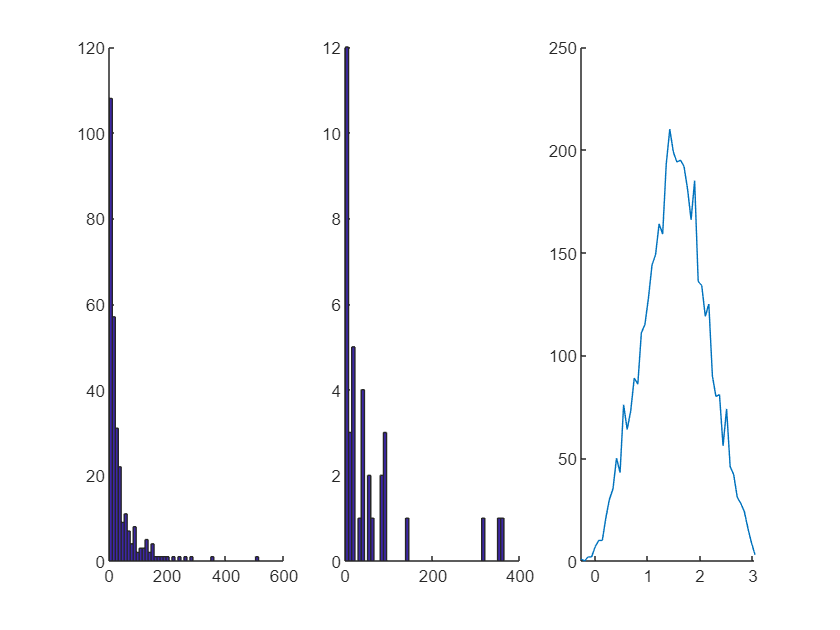

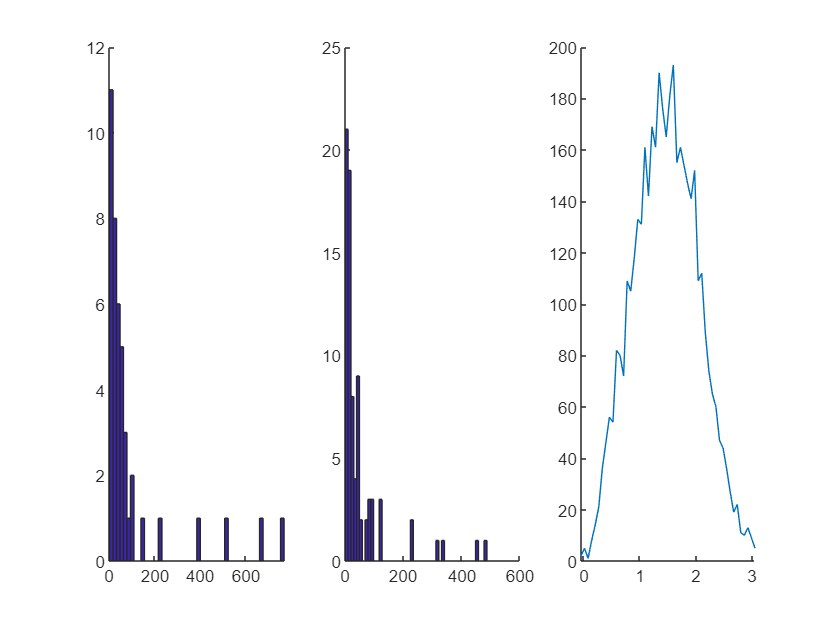

nlen = nan(length(all_IBI),5, 2);
vn = nan(length(all_IBI),5, 2);
vvn = nan(length(all_IBI),5, 2);
svn = nan(length(all_IBI),5, 2);
cvn = nan(length(all_IBI),5, 2);

for n = 1:2
for i = 1:length(all_IBI(:,:,n))
    for j = 1:5
        nlen(i,j,n) = length(all_IBI{i,j,n}); 
        vn(i,j,n) = mean(all_IBI{i,j,n})^2;
        vvn(i,j,n) = var(all_IBI{i,j,n})^2;
        vnn(i,j,n) = var(log(all_IBI{i,j,n}));
        svn(i,j,n) = std(log(all_IBI{i,j,n}));
        cvn(i,j,n) = std(log(all_IBI{i,j,n}))/mean(log(all_IBI{i,j,n}));
    end
end
[~, highind] = max(nlen(:,4,n));
figure
subplot(1,3,1)
hist(all_IBI{highind,4}, 50)
box off
medind = find(nlen(:,4) < median(nlen(:,4)));
[~, medhigh] = max(nlen(medind,4));
medhigh_ind = medind(medhigh);
subplot(1,3,2)
hist(all_IBI{medhigh_ind,4,n}, 50)
box off
all_allIBI = [];
for i = 1:size(all_IBI,1)
%    for j = 1:5
j = 4;
        all_allIBI = [all_allIBI ; all_IBI{i,j,n}];
%    end
end

subplot(1,3,3)

numbins = 50;

[ha hb] = hist(log10(all_allIBI), numbins);
plot(hb,ha);
box off
end


%end
% to look at all plots, used this code:
%for i = 1:7; figure; for j = 1:10; subplot(10,1,j); hist(all_IBI{7*(i-1)+j,4},50); end; end


Conclusion: exponential distribution is probably the best description

(better than gamma)

For an exponential distribution, the mean is 1/delta and variance is 1/delta^2, so variance is mean^2

But variance is tightly connected to number of samples, so use local variance

## Local variance

Cv = std(intervals) /  mean(intervals) 

Lv = 1/(n-1) x sum(3(Ti-Ti+1)^2/(T+Ti+1)^2;

for n = 1:2
LV{n} = nan(size(all_IBI(:,:,n)));
for i = 1:size(all_IBI(:,:,n),1)
    for j = 1:5
        if length(all_IBI{i,j,n}) > 1
            currints = all_IBI{i,j,n};
            diffints = all_IBId{i,j,n}; %currints(1:end-1)-currints(2:end);
            sumints = all_IBIs{i,j,n}; %currints(1:end-1)+currints(2:end);
            LV{n}(i,j) = 1/(length(all_IBI{i,j,n})-1) * sum(3*(diffints.^2)./(sumints.^2));
        end
    end
end
end

#### Show relationship betwen variance scores and number of samples

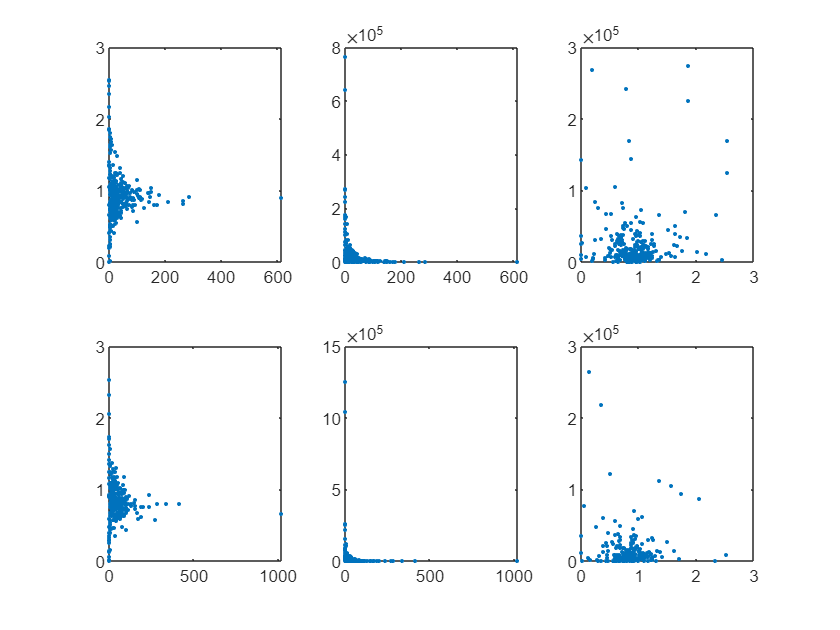

a = -0.0265

b = 0.6470

a = -0.2003

b = 3.0418e-04

a = 0.0996

b = 0.0847

a = -0.0941

b = 0.1231

a = -0.1163

b = 0.0502

a = -0.0573

b = 0.3482

figure
for n = 1:2
    lvr = reshape(LV{n}(:,:),1,[])';
    vnr = reshape(vn(:,:,n), 1, [])';
    nr = reshape(nlen(:,:,n),1,[])';
    lvr_nn = find(~isnan(lvr(:,:)));
    vn_nn = find(~isnan(vnr(:,:)));

    [a b] = corr(lvr(lvr_nn),nr(lvr_nn))
    subplot(2,3,1+(n-1)*3);
    plot(nr, lvr, '.');

    subplot(2,3,2+(n-1)*3);
    plot(nr, vnr, '.');
    subplot(2,3,3+(n-1)*3);
    plot(lvr,vnr, '.')

    [a b] = corr(reshape(vnr(vn_nn),1,[])',reshape(nr(vn_nn),1,[])')
    [a b] = corr(reshape(vnr(intersect(vn_nn, lvr_nn)),1,[])',reshape(lvr(intersect(vn_nn, lvr_nn)),1,[])')
end

Conclusion: Local variance is probably the better measure, because it is not as tightly associated with sample number

### Compare Local Variance between strangers and cagemates, across 5 interaction types

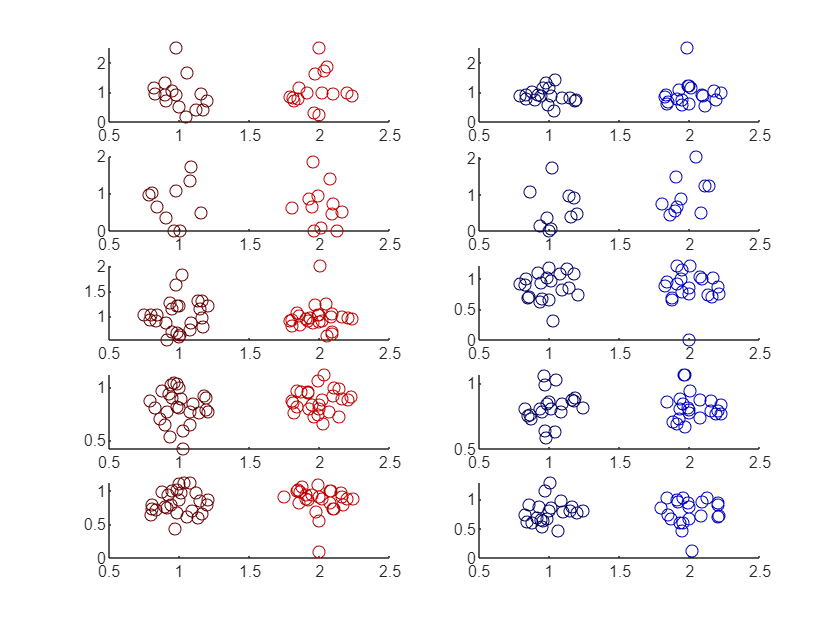

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


pp = 1×5
    0.5684    0.7307    0.6063    0.1317    0.5108


pp2 = 1×5
    0.7268    0.4792    0.0635    0.0714    0.2100


Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


pp = 1×5
    0.6037    0.1345    0.8846    0.9029    0.9939


pp2 = 1×5
    0.9856    0.7618    0.9345    0.3072    0.6885


figure
for n = 1:2
    if n == 1
        lcag = length(cagemates_f);
        cagind = cagemates_f;
        lstr = length(ostrangers_f);
        strind = ostrangers_f;
        colorcodesC = colorcodes_f;
    else
        lcag = length(cagemates_m);
        cagind = cagemates_m;
        lstr = length(ostrangers_m);
        strind = ostrangers_m;
        colorcodesC = colorcodes_m; 
    end


for i = 1:5
    subplot(5,2, 1+(2*(i-1)+(n-1)))
    s{1} = swarmchart(ones(lcag,1), LV{n}(cagind,i), 'MarkerEdgeColor', colorcodesC(2,:));
    hold
    s{2} = swarmchart(2*ones(lstr,1), LV{n}(strind,i), 'MarkerEdgecolor', colorcodesC(1,:));
    for j = 1:2
        set(s{j}, 'XJitterWidth', .5);
    end
    [~, pp(i)] = ttest2(LV{n}(cagind,i), LV{n}(strind,i));
    pp2(i) = ranksum(vn(cagind,i), vn(strind,i));
end
    
pp
pp2
end

Conclusion: No obvious differences between stranger and cagemate in IBI variance

### Repeat for Day 1 IBIs

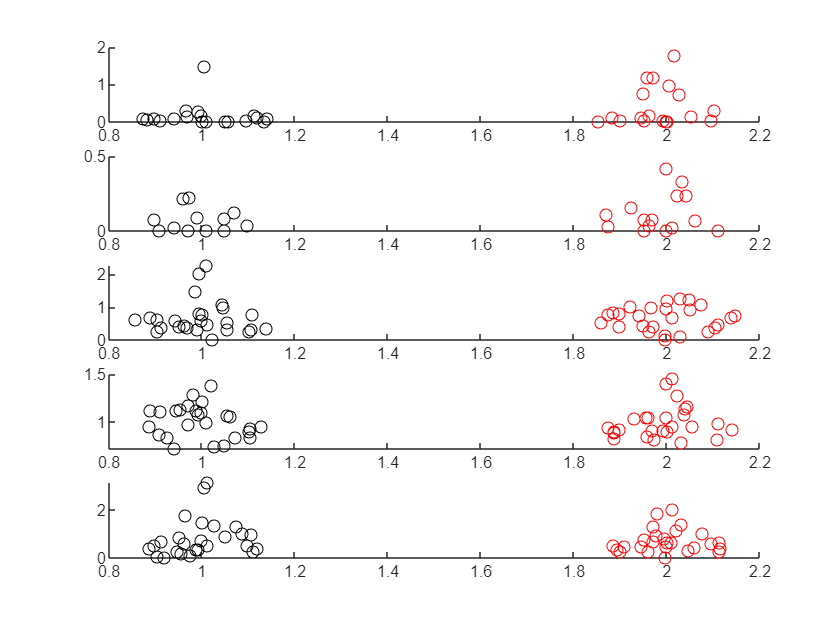

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


%all_IBI 

betypes = [-1 1 2 3 5];

all_IBI_day1 = cell(length(fem_pairs), length(betypes));
for i = 1:length(fem_pairs)
    curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' == 1);   
    for j = 1:length(curind)        
        for k = 1:length(betypes)
            curbehaves = find(fix(rdb_rr.be_identcode(:,curind(j))) == betypes(k));
            IBI = diff(rdb_rr.be_start_end(curbehaves,1,curind(j)));
            all_IBI_day1{i,k} = [all_IBI{i,k} ; IBI];
        end        
    end
end
LVd1 = nan(size(all_IBI));
for i = 1:size(all_IBI,1)
    for j = 1:5
        if length(all_IBI_day1{i,j} > 1)
            currints = all_IBI_day1{i,j};
            LVd1(i,j) = 1/(length(all_IBI_day1{i,4})-1) * sum((3*(currints(1:end-1)-currints(2:end)).^2)./(currints(1:end-1)+currints(2:end)).^2);
            nd1(i,j) = length(all_IBI_day1{i,j});
        end
    end
end

figure
for i = 1:5
    subplot(5,1,i)
    s{1} = swarmchart(ones(length(cagemates_f),1), LVd1(cagemates_f,i), 'k');
    hold
    s{2} = swarmchart(2*ones(length(ostrangers_f),1), LVd1(ostrangers_f,i), 'r');
    for j = 1:2
        set(s{j}, 'XJitterWidth', .3);
    end
    %pp(i) = ranksum(LVd1(cagemates_f,i), LVd1(ostrangers_f,i));
    [~, pp(i)] = ttest2(LVd1(cagemates_f,i), LVd1(ostrangers_f,i));
end

pp

pp = 1×5
    0.0847    0.2713    0.9182    0.8222    0.5310


Again: no apparent differences between groups

## Additional transition matrix calculations

Calculate Eigen values (no longer using)

% 
% E_c_self(:,1) = eig(TMcagall(1:5,1:5));
% E_c_other(:,1) = eig(TMcagall(1:5,7:11));
% E_s_self(:,1) = eig(TMstrall(1:5,1:5));
% E_s_other(:,1) = eig(TMstrall(1:5,7:11));
% 
% E_c_self(:,2) = eig(TMcagall2(1:5,1:5));
% E_c_other(:,2) = eig(TMcagall2(1:5,7:11));
% E_s_self(:,2) = eig(TMstrall2(1:5,1:5));
% E_s_other(:,2) = eig(TMstrall2(1:5,7:11));

Eigen values -- focus on average

% % figure
% % subplot(2,1,1)
% % bar([E_c_self(1,1) E_c_self(1,2) E_s_self(1,1) E_s_self(1,2)]);
% % subplot(2,1,2)
% % bar([E_c_other(1,1) E_c_other(1,2) E_s_other(1,1) E_s_other(1,2)]);
% 

Compare Eigen Values

% TM_f = nan(5,12,length(fem_pairs));
% E_f = nan(5,2,length(fem_pairs));
% for i = 1:length(fem_pairs)
%     curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' < 6);
%     TM_f(:,:,i) = nanmean(TM(:,:,curind),3);
%     TM2_f(:,:,i) = nanmean(TM2(:,:,curind),3);
%     TM_fc(:,:,i) = nanmean(TMc(:,:,curind),3);
%     
%     ttemp_1 = TM_f(:,:,i);
%     ttemp_1(isnan(ttemp_1)) = 0;
%     ttemp_2 = TM2_f(:,:,i);
%     ttemp_2(isnan(ttemp_2)) = 0;
%     
%     E_f_self(:,1,i) = eig(ttemp_1(1:5,1:5));
%     E_f_self(:,2,i) = eig(ttemp_2(1:5,1:5));
%     E_f_other(:,1,i) = eig(ttemp_1(1:5,7:11));
%     E_f_other(:,2,i) = eig(ttemp_2(1:5,7:11));
%     
%     E_f_cont(:,1,i) = eig(TM_fc(1:5,7:11,i));
%         
% end
% 
% figure
% subplot(2,1,1)
% bar(1:4, [nanmean(E_f_self(1,1,cagemates_f)) nanmean(E_f_self(1,2,cagemates_f)) nanmean(E_f_self(1,1,ostrangers_f)) nanmean(E_f_self(1,2,ostrangers_f))]);
% hold on
% errorbar(1:4, [nanmean(E_f_self(1,1,cagemates_f)) nanmean(E_f_self(1,2,cagemates_f)) nanmean(E_f_self(1,1,ostrangers_f)) nanmean(E_f_self(1,2,ostrangers_f))], ...
% [nanstd(E_f_self(1,1,cagemates_f)) nanstd(E_f_self(1,2,cagemates_f)) nanstd(E_f_self(1,1,ostrangers_f)) nanstd(E_f_self(1,2,ostrangers_f))]/sqrt(length(ostrangers_f)-1), 'LineStyle', 'none');
% 
% bar( 5.5, nanmean(E_f_cont(1,1,cagemates_f)));
% errorbar(5.5, nanmean(E_f_cont(1,1,cagemates_f)), nanstd(E_f_cont(1,1,cagemates_f))/sqrt(length(cagemates_f)-1));
% bar( 6.5, nanmean(E_f_cont(1,1,ostrangers_f)));
% errorbar(6.5, nanmean(E_f_cont(1,1,ostrangers_f)), nanstd(E_f_cont(1,1,ostrangers_f))/sqrt(length(ostrangers_f)-1));
% box off
% 
% subplot(2,1,2)
% bar(1:4, [nanmean(E_f_other(1,1,cagemates_f)) nanmean(E_f_other(1,2,cagemates_f)) nanmean(E_f_other(1,1,ostrangers_f)) nanmean(E_f_other(1,2,ostrangers_f))]);
% hold
% errorbar(1:4, [nanmean(E_f_other(1,1,cagemates_f)) nanmean(E_f_other(1,2,cagemates_f)) nanmean(E_f_other(1,1,ostrangers_f)) nanmean(E_f_other(1,2,ostrangers_f))], ...
% [nanstd(E_f_other(1,1,cagemates_f)) nanstd(E_f_other(1,2,cagemates_f)) nanstd(E_f_other(1,1,ostrangers_f)) nanstd(E_f_other(1,2,ostrangers_f))]/sqrt(length(ostrangers_f)-1), 'LineStyle', 'none');
% 
% 
% 
% bar( 5.5, nanmean(E_f_cont(1,1,cagemates_f)));
% errorbar(5.5, nanmean(E_f_cont(1,1,cagemates_f)), nanstd(E_f_cont(1,1,cagemates_f))/sqrt(length(cagemates_f)-1));
% bar( 6.5, nanmean(E_f_cont(1,1,ostrangers_f)));
% errorbar(6.5, nanmean(E_f_cont(1,1,ostrangers_f)), nanstd(E_f_cont(1,1,ostrangers_f))/sqrt(length(ostrangers_f)-1));
% 
% box off

% sns_inds = {indsig_f, indnonsig_f};
% 
% 
% for i = 1:2
% 
% figure
% subplot(2,1,1)
% bar(1:4, [nanmean(E_f_self(1,1,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_self(1,2,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_self(1,1,intersect(ostrangers_f,sns_inds{i}))) nanmean(E_f_self(1,2,intersect(ostrangers_f,sns_inds{i})))]);
% hold on
% errorbar(1:4, [nanmean(E_f_self(1,1,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_self(1,2,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_self(1,1,intersect(ostrangers_f,sns_inds{i}))) nanmean(E_f_self(1,2,intersect(ostrangers_f,sns_inds{i})))], ...
% [nanstd(E_f_self(1,1,intersect(cagemates_f, sns_inds{i}))) nanstd(E_f_self(1,2,intersect(cagemates_f, sns_inds{i}))) nanstd(E_f_self(1,1,intersect(ostrangers_f,sns_inds{i}))) nanstd(E_f_self(1,2,intersect(ostrangers_f,sns_inds{i})))]/sqrt(length(intersect(ostrangers_f,sns_inds{i}))-1), 'LineStyle', 'none');
% 
% bar( 5.5, nanmean(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i}))));
% errorbar(5.5, nanmean(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i}))), nanstd(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i})))/sqrt(length(intersect(cagemates_f, sns_inds{i}))-1));
% bar( 6.5, nanmean(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i}))));
% errorbar(6.5, nanmean(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i}))), nanstd(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i})))/sqrt(length(intersect(ostrangers_f,sns_inds{i}))-1));
% box off
% 
% subplot(2,1,2)
% bar(1:4, [nanmean(E_f_other(1,1,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_other(1,2,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_other(1,1,intersect(ostrangers_f,sns_inds{i}))) nanmean(E_f_other(1,2,intersect(ostrangers_f,sns_inds{i})))]);
% hold
% errorbar(1:4, [nanmean(E_f_other(1,1,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_other(1,2,intersect(cagemates_f, sns_inds{i}))) nanmean(E_f_other(1,1,intersect(ostrangers_f,sns_inds{i}))) nanmean(E_f_other(1,2,intersect(ostrangers_f,sns_inds{i})))], ...
% [nanstd(E_f_other(1,1,intersect(cagemates_f, sns_inds{i}))) nanstd(E_f_other(1,2,intersect(cagemates_f, sns_inds{i}))) nanstd(E_f_other(1,1,intersect(ostrangers_f,sns_inds{i}))) nanstd(E_f_other(1,2,intersect(ostrangers_f,sns_inds{i})))]/sqrt(length(intersect(ostrangers_f,sns_inds{i}))-1), 'LineStyle', 'none');
% 
% 
% 
% bar( 5.5, nanmean(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i}))));
% errorbar(5.5, nanmean(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i}))), nanstd(E_f_cont(1,1,intersect(cagemates_f, sns_inds{i})))/sqrt(length(intersect(cagemates_f, sns_inds{i}))-1));
% bar( 6.5, nanmean(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i}))));
% errorbar(6.5, nanmean(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i}))), nanstd(E_f_cont(1,1,intersect(ostrangers_f,sns_inds{i})))/sqrt(length(intersect(ostrangers_f,sns_inds{i}))-1));
% 
% box off
% end

% E_f_days_self = nan(length(fem_pairs), 5, 2);
% E_f_days_other = nan(length(fem_pairs), 5, 2);
% E_f_days_ctl = nan(length(fem_pairs), 5, 2);
% for i = 1:length(fem_pairs)
%     for j = 1:5
%     curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' == j);
%     TM_f(:,:,i) = nanmean(TM(:,:,curind),3);
%     TM2_f(:,:,i) = nanmean(TM2(:,:,curind),3);
%     TM_fc(:,:,i) = nanmean(TMc(:,:,curind),3);
%     
%     ttemp_1 = TM_f(:,:,i);
%     ttemp_1(isnan(ttemp_1)) = 0;
%     ttemp_2 = TM2_f(:,:,i);
%     ttemp_2(isnan(ttemp_2)) = 0;
%     
%     E = eig(ttemp_1(1:5,1:5));
%     E_f_days_self(i,j,1) = abs(E(1));
%     
%     E = eig(ttemp_2(1:5,1:5));
%     E_f_days_self(i,j,2) = abs(E(1));
%     
%     E = eig(ttemp_1(1:5,7:11));
%     E_f_days_other(i,j,1) = abs(E(1));
%     
%     E = eig(ttemp_2(1:5,7:11));
%     E_f_days_other(i,j,2) = abs(E(1));
%         
%     E = eig(TM_fc(1:5,7:11));
%     E_f_days_ctl(:,1,i) = abs(E(1));
%     
%     end
% end
% 
% figure
% sp1 = subplot(2,1,1);
% errorbar(nanmean(E_f_days_self(cagemates_f,:,1)), nanstd(E_f_days_self(cagemates_f,:,1))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_self(ostrangers_f,:,1)), nanstd(E_f_days_self(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,1)), nanstd(E_f_days_ctl(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% hold off
% set(sp1, 'XLim', [.75 5.25])
% box off
% 
% sp2 = subplot(2,1,2);
% errorbar(nanmean(E_f_days_other(cagemates_f,:,1)), nanstd(E_f_days_other(cagemates_f,:,1))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_other(ostrangers_f,:,1)), nanstd(E_f_days_other(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,1)), nanstd(E_f_days_ctl(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% box off
% set(sp2, 'XLim', [.75 5.25])

% figure
% sp1 = subplot(2,1,1);
% errorbar(nanmean(E_f_days_self(cagemates_f,:,2)), nanstd(E_f_days_self(cagemates_f,:,2))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_self(ostrangers_f,:,2)), nanstd(E_f_days_self(ostrangers_f,:,2))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,2)), nanstd(E_f_days_ctl(ostrangers_f,:,2))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% hold off
% set(sp1, 'XLim', [.75 5.25])
% box off
% 
% sp2 = subplot(2,1,2);
% errorbar(nanmean(E_f_days_other(cagemates_f,:,2)), nanstd(E_f_days_other(cagemates_f,:,2))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_other(ostrangers_f,:,2)), nanstd(E_f_days_other(ostrangers_f,:,2))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,2)), nanstd(E_f_days_ctl(ostrangers_f,:,2))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% box off
% set(sp2, 'XLim', [.75 5.25])
% 

% sns_inds = {indsig_f, indnonsig_f};
% 
% for k = 1:2
%     
% 
% 
% E_f_days_self = nan(length(fem_pairs), 5, 2);
% E_f_days_other = nan(length(fem_pairs), 5, 2);
% E_f_days_ctl = nan(length(fem_pairs), 5, 2);
% for i = 1:length(fem_pairs)
%     for j = 1:5
%     curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' == j);
%     curind = intersect(curind, sns_inds{k});
%     TM_f(:,:,i) = nanmean(TM(:,:,curind),3);
%     TM2_f(:,:,i) = nanmean(TM2(:,:,curind),3);
%     TM_fc(:,:,i) = nanmean(TMc(:,:,curind),3);
%     TM_fc(isinf(TM_fc)) = 0;
%     TM_fc(isnan(TM_fc)) = 0;
%     
%     ttemp_1 = TM_f(:,:,i);
%     ttemp_1(isnan(ttemp_1)) = 0;
%     ttemp_2 = TM2_f(:,:,i);
%     ttemp_2(isnan(ttemp_2)) = 0;
%     
%     E = eig(ttemp_1(1:5,1:5));
%     E_f_days_self(i,j,1) = E(1);
%     
%     E = eig(ttemp_2(1:5,1:5));
%     E_f_days_self(i,j,2) = E(1);
%     
%     E = eig(ttemp_1(1:5,7:11));
%     E_f_days_other(i,j,1) = E(1);
%     
%     E = eig(ttemp_2(1:5,7:11));
%     E_f_days_other(i,j,2) = E(1);
%         
%     
%     E = eig(TM_fc(1:5,7:11));
%     E_f_days_ctl(:,1,i) = E(1);
%     
%     end
% end
% 
% 
% figure
% sp1 = subplot(2,1,1);
% errorbar(nanmean(E_f_days_self(cagemates_f,:,1)), nanstd(E_f_days_self(cagemates_f,:,1))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_self(ostrangers_f,:,1)), nanstd(E_f_days_self(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,1)), nanstd(E_f_days_ctl(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% hold off
% set(sp1, 'XLim', [.75 5.25]);
% box off
% 
% sp2 = subplot(2,1,2);
% errorbar(nanmean(E_f_days_other(cagemates_f,:,1)), nanstd(E_f_days_other(cagemates_f,:,1))/sqrt(length(cagemates_f)-1), 'k');
% hold on
% errorbar(nanmean(E_f_days_other(ostrangers_f,:,1)), nanstd(E_f_days_other(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'r');
% errorbar(nanmean(E_f_days_ctl(ostrangers_f,:,1)), nanstd(E_f_days_ctl(ostrangers_f,:,1))/sqrt(length(ostrangers_f)-1), 'Color', [.5 .5 .5]);
% box off
% set(sp2, 'XLim', [.75 5.25]);
% 
% 
% end

% TMcagall = nanmean(TM(:,:,intersect(intersect(fem_ind, cagemateind), indsig_rr)),3);
% TMcagall2 = nanmean(TM2(:,:,intersect(intersect(fem_ind, cagemateind), indsig_rr)),3);
% TMstrall = nanmean(TM(:,:,intersect(intersect(fem_ind, oldstrangerind), indsig_rr)),3);
% TMstrall2 = nanmean(TM2(:,:,intersect(intersect(fem_ind, oldstrangerind), indsig_rr)),3);
% 
% figure
% imagesc([[TMcagall(:,[1:5 7:11]) ; TMcagall2(:,[1:5 7:11])]  [TMstrall(:,[1:5 7:11]) ; TMstrall2(:,[1:5 7:11])]]);
% 

% 
% figure
% subplot(2,1,1)
% bar(1:4, abs([nanmean(E_f_self(2,1,cagemates_f)) nanmean(E_f_self(2,2,cagemates_f)) nanmean(E_f_self(2,1,ostrangers_f)) nanmean(E_f_self(2,2,ostrangers_f))]));
% hold on
% errorbar(1:4, abs([nanmean(E_f_self(2,1,cagemates_f)) nanmean(E_f_self(2,2,cagemates_f)) nanmean(E_f_self(2,1,ostrangers_f)) nanmean(E_f_self(2,2,ostrangers_f))]), ...
% abs([nanstd(E_f_self(2,1,cagemates_f)) nanstd(E_f_self(2,2,cagemates_f)) nanstd(E_f_self(2,1,ostrangers_f)) nanstd(E_f_self(2,2,ostrangers_f))])/sqrt(length(ostrangers_f)-1), 'LineStyle', 'none');
% 
% bar( 5.5, nanmean(E_f_cont(2,1,cagemates_f)));
% errorbar(5.5, nanmean(E_f_cont(2,1,cagemates_f)), nanstd(E_f_cont(2,1,cagemates_f))/sqrt(length(cagemates_f)-1));
% bar( 6.5, nanmean(E_f_cont(2,1,ostrangers_f)));
% errorbar(6.5, nanmean(E_f_cont(2,1,ostrangers_f)), nanstd(E_f_cont(2,1,ostrangers_f))/sqrt(length(ostrangers_f)-1));
% box off
% 
% subplot(2,1,2)
% bar(1:4, abs([nanmean(E_f_other(2,1,cagemates_f)) nanmean(E_f_other(2,2,cagemates_f)) nanmean(E_f_other(2,1,ostrangers_f)) nanmean(E_f_other(2,2,ostrangers_f))]));
% hold
% errorbar(1:4, abs([nanmean(E_f_other(2,1,cagemates_f)) nanmean(E_f_other(2,2,cagemates_f)) nanmean(E_f_other(2,1,ostrangers_f)) nanmean(E_f_other(2,2,ostrangers_f))]), ...
% abs([nanstd(E_f_other(2,1,cagemates_f)) nanstd(E_f_other(2,2,cagemates_f)) nanstd(E_f_other(2,1,ostrangers_f)) nanstd(E_f_other(2,2,ostrangers_f))])/sqrt(length(ostrangers_f)-1), 'LineStyle', 'none');
% 
% 
% 
% bar( 5.5, nanmean(E_f_cont(2,1,cagemates_f)));
% errorbar(5.5, nanmean(E_f_cont(2,1,cagemates_f)), nanstd(E_f_cont(2,1,cagemates_f))/sqrt(length(cagemates_f)-1));
% bar( 6.5, nanmean(E_f_cont(2,1,ostrangers_f)));
% errorbar(6.5, nanmean(E_f_cont(2,1,ostrangers_f)), nanstd(E_f_cont(2,1,ostrangers_f))/sqrt(length(ostrangers_f)-1));
% 
% box off

% TMcagall = nanmean(TM(:,:,intersect(fem_ind, intersect(cagemateind, indnonsig_rr_f))),3);
% TMcagall2 = nanmean(TM2(:,:,intersect(fem_ind, intersect(cagemateind, indnonsig_rr_f))),3);
% TMstrall = nanmean(TM(:,:,intersect(fem_ind, intersect(oldstrangerind, indnonsig_rr_f))),3);
% TMstrall2 = nanmean(TM2(:,:,intersect(fem_ind, intersect(oldstrangerind, indnonsig_rr_f))),3);
% 
% figure
% imagesc([[TMcagall(:,[1:5 7:11]) ; TMcagall2(:,[1:5 7:11])]  [TMstrall(:,[1:5 7:11]) ; TMstrall2(:,[1:5 7:11])]]);

Calculate the covariance and correlation coefficients (no longer using)

% betypes = [-1 1 2 3 5]; % just in case it's changed...
% 
% cumsumbehav = Rdb_CumSum(rdb_rr, betypes, 1);

% 
% scb = size(cumsumbehav,3);
% 
% covBehave = nan(scb,scb,length(rdb_rr.paircode));
% rcvB = nan(length(rdb_rr.paircode), scb*scb);
% for i = 1:length(rdb_rr.paircode)
%     dcum = diff(squeeze(cumsumbehav(i,:,:)));
%     dcum2 = dcum+[zeros(1,scb) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,scb)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors
%     dcumT = dcum2 > 0;
%     cvb = cov(dcumT);
%     %cvb(find(eye(size(dcumT,2)))) = nan;
%     covBehave(:,:,i) = cvb;
%     rcvB(i,:) = reshape(cvb, 1, []);
% end

% figure
% nmcoB = nanmean(covBehave(:,:,fem_ind), 3);
% nmcoB(find(eye(length(nmcoB)))) = nan;
% imagesc(nmcoB);
% 
% vec_int_pairs = [2 3 4 5 7 8 9 13 14 19]; %a-g, a-r, a-f, a-s, g-r, g-f, g-s, r-f, r-s, f-s
% lvp = length(vec_int_pairs);
% 
% figure
% e1 = errorbar(1:lvp, nanmean(rcvB(fem_ind,vec_int_pairs)), nanstd(rcvB(fem_ind,vec_int_pairs))/sqrt(length(fem_ind)-1));
% set(get(e1, 'Parent'), 'XLim', [0.5 lvp+.5]);
% box off
% clear pcov dfB tstatB
% for i = 1:lvp
%     [~, pcov(i), ~, tcov] = ttest(rcvB(fem_ind,vec_int_pairs(i)));
%     dfB(i) = tcov.df;
%     tstatB(i) = tcov.tstat;
% end
% pcov < 0.0025
% dfB
% tstatB
% 
% 

% cumsumbehavID = Rdb_CumSum(rdb_rr, betypes, 0);
% scb = size(cumsumbehavID,3);
% 
% corrBehave = nan(scb,scb,length(rdb_rr.paircode));
% cBi = nan(length(rdb_rr.paircode), 1);
% rcB = nan(length(rdb_rr.paircode), 81);
% for i = 1:length(rdb_rr.paircode)
%     dcum = diff(squeeze(cumsumbehavID(i,:,:)));
%     dcum2 = dcum+[zeros(1,9) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,9)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors
%     dcumT = dcum2 > 0;
%     cvb = cov(dcumT);
%     cb = corr(dcumT);
%     cb(find(eye(size(dcumT,2)))) = nan;
%     corrBehave(:,:,i) = cb;
%     rcB(i,:) = reshape(cb, 1, []);
%     cBi(i) = max(max(abs(corrBehave([1 2 3 4 9], [5 6 7 8 9],i))));
% end

% cBi_mat = nan(length(fem_pairs), 5);
% corrBmat = nan(length(fem_pairs), 5, size(corrBehave,1) * size(corrBehave,2));
% for i = 1:length(fem_pairs)
%     for j = 1:5
%         curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' == j);
%         if ~isempty(curind)
%           %  corrBmat(i,j,:) = reshape(corrBmat(:,:,curind), 1, [])
%             cBi_mat(i,j) = cBi(curind);        
%         end
%     end
% end
% 
% cBi_mat3 = cBi_mat.^(1/3)
% 
% 
% figure
% hold
% ee1 = errorbar(1:5, nanmean(cBi_mat(ostrangers_f,:)), nanstd(cBi_mat(ostrangers_f, :))/sqrt(length(ostrangers_f)) , 'r');
% ee2 = errorbar(1:5, nanmean(cBi_mat(cagemates_f,:)), nanstd(cBi_mat(cagemates_f, :))/sqrt(length(cagemates_f)) , 'k');
% ee3 = errorbar(1:2, nanmean(cBi_mat(nstrangers_f,1:2)), nanstd(cBi_mat(nstrangers_f, 1:2))/sqrt(length(nstrangers_f)), 'b');
% set(get(ee1, 'Parent'), 'XLim', [0.75 5.25])
% anovacell{1} = reshape([cBi_mat(ostrangers_f, :) ; cBi_mat(cagemates_f, :)], 1, []);
% anovacell{2} = reshape([ones(length(ostrangers_f),5) ; 2*ones(length(cagemates_f), 5)], 1, []);
% anovacell{3} = reshape(repmat(1:5, length(ostrangers_f)+length(cagemates_f), 1), 1, []);
% 
% [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');
% 
% ee1 = errorbar(1:5, nanmean(cBi_mat3(ostrangers_f,:)), nanstd(cBi_mat3(ostrangers_f, :))/sqrt(length(ostrangers_f)) , 'r');
% ee2 = errorbar(1:5, nanmean(cBi_mat3(cagemates_f,:)), nanstd(cBi_mat3(cagemates_f, :))/sqrt(length(cagemates_f)) , 'k');
% ee3 = errorbar(1:2, nanmean(cBi_mat3(nstrangers_f,1:2)), nanstd(cBi_mat3(nstrangers_f, 1:2))/sqrt(length(nstrangers_f)), 'b');
% set(get(ee1, 'Parent'), 'XLim', [0.75 5.25])
% anovacell{1} = reshape([cBi_mat3(ostrangers_f, :) ; cBi_mat3(cagemates_f, :)], 1, []);
% anovacell{2} = reshape([ones(length(ostrangers_f),5) ; 2*ones(length(cagemates_f), 5)], 1, []);
% anovacell{3} = reshape(repmat(1:5, length(ostrangers_f)+length(cagemates_f), 1), 1, []);
% 
% [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

